%Ergasia 2
%Γεωργακακη Μαρια       ΑΜ:58283
%Τσικοπουλου Σταυρουλα  ΑΜ:58306
%Καπουσουζη Αθανασια    ΑΜ:58392
%Πουλιος Νικολαος       ΑΜ:58494

%Askisi 1.a
clc; clear;

[x, Fs]=audioread('voice.wav');

%soundsc(x, Fs)
X=frame_wind(x, 256, 0.25); 

for f=1:255 %Βαζουμε 255 αντι για 256 γιατι με 256 frames 
            % ολα τα στοιχεια του a πλην του πρωτου βγαινουν NaN
    [a,g]=lpc_new(X(f, :),29);%βαζουμε 29 γιατι αρχιζει να μετραει απο το 0
end
a 

a =      1
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


g

g = NaN

%Askisi 1.b
clc; clear;

[x, Fs1]=audioread('piano_samples.wav');

mf1=mfcc(x, Fs1, "NumCoeffs", 29) %συντελεστες για το πιανο

mf1 =   -14.9251  -33.1280    0.1322   -0.6195   -0.4154    0.2098   -0.2322   -0.2978   -0.4208   -0.1303    0.4042    0.2844    0.2718    0.0734   -0.0133    0.0476    0.3104   -0.2138    0.0612   -0.0830   -0.5254   -0.1728   -0.1599   -0.1986   -0.1879    0.0204   -0.0483    0.0353    0.0353    0.1067
  -14.4453  -31.2876    0.6067   -0.7883   -0.4825    0.2235   -0.1905    0.0070   -0.2978   -0.4551    0.1129    0.0364    0.0643    0.0887    0.0254    0.0313    0.2567   -0.0273   -0.1213    0.0081   -0.0856    0.1853   -0.0203   -0.1635    0.0212    0.1999   -0.0703   -0.0510   -0.0131    0.1009
   -6.4767  -23.5082    2.1136   -0.6468   -0.0270    0.4352    0.1802    0.0510    0.0706   -0.1811   -0.0451   -0.0175    0.0627    0.2616    0.2943    0.1885    0.0756   -0.0911   -0.1021   -0.0213    0.1168    0.2054    0.2230    0.0951    0.0028   -0.0834   -0.0807   -0.0787   -0.0335    0.0222
   -3.9538  -18.7442    3.1305   -0.0788    0.1518    0.3952    0.0140   -0.0334    0.1635 


%Askisi 1.c
[y, Fs2]=audioread('cello_samples.wav');
[z, Fs3]=audioread('flute_samples.wav');
[u, Fs4]=audioread('e_guitar_samples.wav');

mf2=mfcc(y, Fs2, "NumCoeffs", 29) %συντελεστες για το τσελλο

mf2 =     1.4849  -13.0102    4.4356   -0.7347    0.9538    0.1726    0.0133   -0.0183    0.5600    0.7346   -0.3136   -0.0338    0.2349    0.1257    0.1197    0.3146   -0.0910   -0.2688   -0.3408   -0.4764   -0.3524   -0.2793   -0.2037   -0.0969    0.1144    0.2653    0.0352   -0.0470    0.0237    0.1136
    1.5328  -13.0954    4.4829   -0.5550    0.8834    0.2882   -0.2024   -0.1218    0.6779    0.6644   -0.3722   -0.0313    0.2432    0.1262    0.1491    0.2961   -0.1593   -0.3017   -0.3249   -0.3811   -0.3401   -0.2787   -0.2063   -0.1867    0.0316    0.2912    0.0364   -0.1097   -0.0716    0.0589
    1.5193  -13.4952    4.7872   -0.7210    1.0176    0.1798   -0.3496   -0.1268    0.7751    0.8179   -0.4137   -0.0048    0.2154    0.1476    0.1616    0.3196   -0.2391   -0.3169   -0.1896   -0.4877   -0.2552   -0.4129   -0.3310   -0.2573   -0.0450    0.2988   -0.0321   -0.1326   -0.0354    0.0132
    1.6836  -13.3040    4.3197   -0.6066    0.8983   -0.0503   -0.2545   -0.0059    0.8707 

mf3=mfcc(z, Fs3, "NumCoeffs", 29) %συντελεστες για το φλαουτο

mf3 =     0.0032  -17.9394    3.0359   -2.2210   -0.6171   -1.2527    0.0837    1.1595   -0.1011   -0.4800   -0.7682   -0.2627    0.9944    0.0280    0.1061    0.3321   -0.5207    0.0764    0.4434    0.0621    0.0703   -0.0787   -0.1414    0.0553   -0.2613    0.2131   -0.0674   -0.1975    0.4240   -0.0084
    1.4103  -15.2536    2.8972   -2.2952   -0.9689   -1.4155   -0.3890    0.7144   -0.1356   -0.2420   -1.0685   -0.7474    1.1358    0.1529   -0.0388    0.3074   -0.6797   -0.0049    0.7004    0.1213   -0.0473   -0.2056   -0.2758   -0.1166   -0.1294    0.6099   -0.3993   -0.5825    0.4161   -0.0082
    1.8485  -14.6430    3.2645   -2.4585   -0.9669   -1.0281   -0.3955    0.4595    0.1662   -0.1165   -1.1776   -0.9148    0.9719    0.2089    0.1385    0.4191   -0.7933   -0.1376    0.7916    0.1832    0.0676   -0.0999   -0.0997    0.0498   -0.1813    0.7668   -0.3946   -0.6395    0.2707   -0.0275
    1.8142  -14.8567    2.9813   -2.5524   -0.7809   -0.9142   -0.5674    0.3134    0.7973 

mf4=mfcc(u, Fs4, "NumCoeffs", 29) %συντελεστες για την ηλεκτρικη κιθαρα

mf4 =     1.6467  -14.7067    2.5551    0.4326    0.5260    0.5507    1.0052    0.0913   -0.8842   -0.9568   -0.0583   -0.4936   -0.1434   -0.9248   -0.9787   -0.0424    0.2686   -0.2689    0.2667   -0.0086   -0.5145    0.4241    0.3416   -0.2264    0.1143   -0.2164    0.2258    0.0893   -0.1498    0.1776
    2.7912  -11.9440    1.9675    0.4738    0.4593    0.3557    1.0450    0.3583   -0.6805   -0.9122   -0.1252   -0.6008   -0.3798   -1.3550   -1.2428   -0.1070    0.3344   -0.1374    0.2995   -0.0654   -0.5250    0.4833    0.5901   -0.1839    0.1088    0.2421    0.6224   -0.0251   -0.2669    0.1220
    3.3091  -10.5609    1.8600    0.2553    0.5571    0.0569    0.6857    0.4256   -0.1117   -0.8774   -0.3615   -0.5882   -0.1504   -1.3372   -1.2417   -0.1376    0.2038    0.3475    0.4384   -0.1194   -0.1445    0.5023    0.4980   -0.1213    0.0592    0.4646    0.5348   -0.2321   -0.2193    0.0403
    3.4917   -9.5203    2.0826   -0.2084    0.5896   -0.0923    0.9602    0.2942    0.0480 


%tot=οι πρωτες 4000 σειρες του πινακα (διανυσματα εκμαθησης)
%ver=οι τελευταιες 283 σειρες του πινακα (διανυσματα επαληθευσης)
%m=ταυτοτητα οργανου (προτυπο διανυσμα)
%d=ευκλειδια αποσταση (ver, m)

%Οριζουμε τα διανυσματα εκμαθησης
tot1=mf1;
tot1(4001:end, :)=[]

tot1 =   -14.9251  -33.1280    0.1322   -0.6195   -0.4154    0.2098   -0.2322   -0.2978   -0.4208   -0.1303    0.4042    0.2844    0.2718    0.0734   -0.0133    0.0476    0.3104   -0.2138    0.0612   -0.0830   -0.5254   -0.1728   -0.1599   -0.1986   -0.1879    0.0204   -0.0483    0.0353    0.0353    0.1067
  -14.4453  -31.2876    0.6067   -0.7883   -0.4825    0.2235   -0.1905    0.0070   -0.2978   -0.4551    0.1129    0.0364    0.0643    0.0887    0.0254    0.0313    0.2567   -0.0273   -0.1213    0.0081   -0.0856    0.1853   -0.0203   -0.1635    0.0212    0.1999   -0.0703   -0.0510   -0.0131    0.1009
   -6.4767  -23.5082    2.1136   -0.6468   -0.0270    0.4352    0.1802    0.0510    0.0706   -0.1811   -0.0451   -0.0175    0.0627    0.2616    0.2943    0.1885    0.0756   -0.0911   -0.1021   -0.0213    0.1168    0.2054    0.2230    0.0951    0.0028   -0.0834   -0.0807   -0.0787   -0.0335    0.0222
   -3.9538  -18.7442    3.1305   -0.0788    0.1518    0.3952    0.0140   -0.0334    0.1635


tot2=mf2;
tot2(4001:end, :)=[]

tot2 =     1.4849  -13.0102    4.4356   -0.7347    0.9538    0.1726    0.0133   -0.0183    0.5600    0.7346   -0.3136   -0.0338    0.2349    0.1257    0.1197    0.3146   -0.0910   -0.2688   -0.3408   -0.4764   -0.3524   -0.2793   -0.2037   -0.0969    0.1144    0.2653    0.0352   -0.0470    0.0237    0.1136
    1.5328  -13.0954    4.4829   -0.5550    0.8834    0.2882   -0.2024   -0.1218    0.6779    0.6644   -0.3722   -0.0313    0.2432    0.1262    0.1491    0.2961   -0.1593   -0.3017   -0.3249   -0.3811   -0.3401   -0.2787   -0.2063   -0.1867    0.0316    0.2912    0.0364   -0.1097   -0.0716    0.0589
    1.5193  -13.4952    4.7872   -0.7210    1.0176    0.1798   -0.3496   -0.1268    0.7751    0.8179   -0.4137   -0.0048    0.2154    0.1476    0.1616    0.3196   -0.2391   -0.3169   -0.1896   -0.4877   -0.2552   -0.4129   -0.3310   -0.2573   -0.0450    0.2988   -0.0321   -0.1326   -0.0354    0.0132
    1.6836  -13.3040    4.3197   -0.6066    0.8983   -0.0503   -0.2545   -0.0059    0.8707


tot3=mf3;
tot3(4001:end, :)=[]

tot3 =     0.0032  -17.9394    3.0359   -2.2210   -0.6171   -1.2527    0.0837    1.1595   -0.1011   -0.4800   -0.7682   -0.2627    0.9944    0.0280    0.1061    0.3321   -0.5207    0.0764    0.4434    0.0621    0.0703   -0.0787   -0.1414    0.0553   -0.2613    0.2131   -0.0674   -0.1975    0.4240   -0.0084
    1.4103  -15.2536    2.8972   -2.2952   -0.9689   -1.4155   -0.3890    0.7144   -0.1356   -0.2420   -1.0685   -0.7474    1.1358    0.1529   -0.0388    0.3074   -0.6797   -0.0049    0.7004    0.1213   -0.0473   -0.2056   -0.2758   -0.1166   -0.1294    0.6099   -0.3993   -0.5825    0.4161   -0.0082
    1.8485  -14.6430    3.2645   -2.4585   -0.9669   -1.0281   -0.3955    0.4595    0.1662   -0.1165   -1.1776   -0.9148    0.9719    0.2089    0.1385    0.4191   -0.7933   -0.1376    0.7916    0.1832    0.0676   -0.0999   -0.0997    0.0498   -0.1813    0.7668   -0.3946   -0.6395    0.2707   -0.0275
    1.8142  -14.8567    2.9813   -2.5524   -0.7809   -0.9142   -0.5674    0.3134    0.7973


tot4=mf4;
tot4(4001:end, :)=[]

tot4 =     1.6467  -14.7067    2.5551    0.4326    0.5260    0.5507    1.0052    0.0913   -0.8842   -0.9568   -0.0583   -0.4936   -0.1434   -0.9248   -0.9787   -0.0424    0.2686   -0.2689    0.2667   -0.0086   -0.5145    0.4241    0.3416   -0.2264    0.1143   -0.2164    0.2258    0.0893   -0.1498    0.1776
    2.7912  -11.9440    1.9675    0.4738    0.4593    0.3557    1.0450    0.3583   -0.6805   -0.9122   -0.1252   -0.6008   -0.3798   -1.3550   -1.2428   -0.1070    0.3344   -0.1374    0.2995   -0.0654   -0.5250    0.4833    0.5901   -0.1839    0.1088    0.2421    0.6224   -0.0251   -0.2669    0.1220
    3.3091  -10.5609    1.8600    0.2553    0.5571    0.0569    0.6857    0.4256   -0.1117   -0.8774   -0.3615   -0.5882   -0.1504   -1.3372   -1.2417   -0.1376    0.2038    0.3475    0.4384   -0.1194   -0.1445    0.5023    0.4980   -0.1213    0.0592    0.4646    0.5348   -0.2321   -0.2193    0.0403
    3.4917   -9.5203    2.0826   -0.2084    0.5896   -0.0923    0.9602    0.2942    0.0480


[rows, cols]=size(mf1)

rows = 4283

cols = 30


%Βρισκουμε τα προτυπα διανυσματα
m1=(1/4000)*sum(tot1); %για το πιανο
m1

m1 =    -0.1264  -17.6425    6.0594    0.0158    0.4693    0.0313   -0.3897   -0.1636    0.1757   -0.0344   -0.1351    0.0355    0.0776    0.0290    0.0981    0.0095   -0.0983   -0.0371   -0.0420   -0.2112   -0.1811   -0.0117    0.0411   -0.0014    0.1106    0.0507   -0.0912   -0.0607    0.0004    0.0151



m2=(1/4000)*sum(tot2);%για το τσελο
m2

m2 =     0.8472  -13.5940    4.1021   -0.9068    1.0832    0.2076    0.1499    0.2090    0.2509    0.2034   -0.0126    0.0421    0.0210    0.0373   -0.0004    0.1470    0.0935   -0.0118    0.0204   -0.0679   -0.1125   -0.0337    0.0478   -0.0388    0.0527    0.0457    0.0505   -0.0275    0.0193   -0.0099



m3=(1/4000)*sum(tot3);%για το φλαουτο
m3

m3 =     0.5834  -15.3590    3.3319   -1.4718   -0.3442   -0.6057   -0.3582   -0.4273   -0.0410   -0.2661   -0.1286   -0.1895   -0.1429   -0.0756    0.0337   -0.0273   -0.1056   -0.1560   -0.0188    0.0117    0.1137    0.0937    0.0412    0.0173   -0.1067    0.0627    0.0924   -0.0465   -0.0557   -0.0224



m4=(1/4000)*sum(tot4);%για την κιθαρα
m4

m4 =     3.0003   -8.6881    2.1250   -0.2462    0.2074   -0.2096    0.6376    0.4532    0.2798   -0.1564    0.2451   -0.1091    0.2306   -0.2573    0.0090    0.0573   -0.1627   -0.0492    0.1284   -0.0916    0.1399    0.1633    0.0290   -0.0603    0.2180    0.0787    0.0684   -0.1147    0.1440    0.0816



%Οριζουμε τα διανυσματα επαληθευσης
ver1=mf1;
ver1(1:4000, :)=[]

ver1 =    -3.0506  -21.8298    5.7748    1.4266    0.2534    0.2989    0.0770    0.0631    0.3753    0.2644   -0.0123   -0.1284   -0.3040   -0.2824    0.1574    0.3838    0.1777   -0.1678   -0.2145   -0.1154    0.0738    0.1397    0.0138    0.0845    0.3192    0.3419    0.2101   -0.0011   -0.3294   -0.5994
   -3.0202  -22.4164    6.1612    1.4491    0.0344    0.3211    0.1755   -0.1071    0.4370    0.3313   -0.0648    0.0301   -0.3403   -0.2933    0.2710    0.5054    0.1369   -0.1985   -0.0533   -0.2659    0.0127    0.1907   -0.1276   -0.0423    0.1748    0.4183    0.2866    0.1668   -0.3339   -0.6916
   -3.0327  -22.2166    5.9915    1.4317    0.0863    0.1600    0.1677   -0.1290    0.5938    0.2764    0.0612   -0.1577   -0.3549   -0.2400    0.3868    0.5112    0.1754   -0.1895   -0.0876   -0.0825    0.0349    0.3893   -0.0187   -0.0326    0.1874    0.3886    0.1941    0.0320   -0.3397   -0.7138
   -3.1487  -22.5762    5.9713    1.5484    0.0480    0.2609    0.2555   -0.0783    0.6434


ver2=mf2;
ver2(1:4000, :)=[]

ver2 =     1.9080  -11.9703    3.8126   -0.9328    1.4799    0.6387   -0.1411    0.0182   -0.1291   -0.3755    0.0581    0.3359   -0.4985   -0.2024    0.1818    0.3751    0.2805    0.0723    0.0859    0.0741   -0.0128    0.0047    0.5765    0.1512    0.6354    0.5268    0.2424    0.0374   -0.1223   -0.6596
    1.8675  -11.8993    3.9678   -0.8632    1.5305    0.5535   -0.1031   -0.0243   -0.2053   -0.3468    0.3338    0.3864   -0.4034   -0.3523    0.1446    0.3246    0.3252    0.0608    0.1337    0.0395   -0.1185   -0.0323    0.5694    0.2933    0.6456    0.5073    0.3028   -0.0059   -0.3273   -0.7504
    1.8504  -11.8463    3.8280   -0.9080    1.6516    0.4783    0.0279   -0.1451   -0.2146   -0.3144    0.0786    0.3981   -0.3293   -0.3230    0.1700    0.2606    0.2590    0.0856    0.2632    0.1114   -0.0946   -0.1270    0.5769    0.2120    0.5394    0.4283    0.3212   -0.0057   -0.1111   -0.6189
    1.8413  -11.7379    3.5410   -0.9780    1.6530    0.4755   -0.0447   -0.2071   -0.2245


ver3=mf3;
ver3(1:4000, :)=[]

ver3 =    -0.1739  -14.9314    2.5416   -2.0432   -0.2529   -0.9691   -1.2297   -0.6872    0.0003    0.5858    0.6126   -0.1581   -0.2019    0.4769   -0.0364   -0.0850    0.7576   -0.0472   -0.8003   -0.0167   -0.0899   -0.1719    0.2933   -0.2457    0.2912    0.4181   -0.5957   -0.3084    0.2980   -0.0051
   -0.0368  -13.9070    2.4012   -1.2716   -0.2374   -0.4211   -0.8013   -0.5943    0.4611    0.4590    0.4264   -0.2864   -0.0759    0.3014    0.0651    0.0349    0.5477    0.1492   -0.6273   -0.0839   -0.2270   -0.3618    0.2265   -0.1998    0.1131    0.2135   -0.2344   -0.4124    0.2941   -0.1470
    0.2973  -13.2921    1.7937   -1.2129   -0.5002   -0.7379   -0.7791   -0.5454    0.7904    0.5997    0.4897   -0.3138   -0.0626    0.2063    0.3926    0.0904    0.2748    0.2876   -0.2533   -0.1688   -0.2857   -0.3928   -0.1085    0.0050    0.0745    0.1643   -0.1505   -0.2528   -0.0530   -0.3665
    0.7400  -13.6204    2.0299   -1.3955   -1.0722   -1.4624   -0.7953   -0.3356    0.5794


ver4=mf4;
ver4(1:4000, :)=[]

ver4 =     2.5447  -12.2839    3.1936   -0.2142    0.8570   -0.1493   -0.0914    0.6621    0.7782    0.1856    0.2674    0.2701   -0.1036   -0.1367    0.4575    0.3996    0.0041   -0.0236    0.1922   -0.0445    0.2159    0.3282    0.3099   -0.0633    0.0979   -0.2303    0.0527   -0.0696   -0.0421    0.0306
    1.9156  -13.0719    3.2237   -0.4267    0.6819   -0.0863   -0.0595    0.2930    0.3175   -0.2499   -0.0193    0.0828    0.2559   -0.1290    0.5019    0.4506    0.1388   -0.0154    0.0263   -0.1576   -0.1424    0.0064    0.0785   -0.1518   -0.0950   -0.0109    0.1223    0.2125    0.0864    0.1478
    1.3986  -13.2506    3.2600   -0.2008    0.5419   -0.1831    0.0342    0.2017    0.0840   -0.4174    0.0779    0.3165    0.1955   -0.2014    0.3165    0.4137   -0.0317   -0.1241   -0.0296   -0.2626   -0.0121    0.0148   -0.0031   -0.1332   -0.1290   -0.0086   -0.0483   -0.0389    0.2430    0.2036
    3.6940  -10.9309    4.1483   -0.7525    0.0615   -0.2038    0.5266    0.5669    0.3051


[rows1, cols1]=size(ver1)

rows1 = 283

cols1 = 30


cell11=0;
cell12=0;
cell13=0;
cell14=0;

%Για το πιανο
for f=1:rows1
d11=pdist2(ver1(f, :), m1);
d12=pdist2(ver1(f, :), m2);
d13=pdist2(ver1(f, :), m3);
d14=pdist2(ver1(f, :), m4);

elaxisti_apostasi=min([d11, d12, d13, d14]);
    if elaxisti_apostasi==d11
        cell11=cell11+1;
        else if elaxisti_apostasi==d12
                cell12=cell12+1;
            else if elaxisti_apostasi==d13
                    cell13=cell13+1;
                else if elaxisti_apostasi==d14
                        cell14=cell14+1;
                end
            end
        end
    end
end
win_percentage1=(cell11/283)*100

win_percentage1 = 100


%Για το τσελλο
cell21=0;
cell22=0;
cell23=0;
cell24=0;

for f=1:rows1
d21=pdist2(ver2(f, :), m1);
d22=pdist2(ver2(f, :), m2);
d23=pdist2(ver2(f, :), m3);
d24=pdist2(ver2(f, :), m4);

elaxisti_apostasi=min([d21, d22, d23, d24]);
    if elaxisti_apostasi==d21
        cell21=cell21+1;
        else if elaxisti_apostasi==d22
                cell22=cell22+1;
            else if elaxisti_apostasi==d23
                    cell23=cell23+1;
                else if elaxisti_apostasi==d24
                        cell24=cell24+1;
                end
            end
        end
    end
end
win_percentage2=(cell22/283)*100

win_percentage2 = 100


cell31=0;
cell32=0;
cell33=0;
cell34=0;

%Για το φλαουτο
for f=1:rows1
d31=pdist2(ver3(f, :), m1);
d32=pdist2(ver3(f, :), m2);
d33=pdist2(ver3(f, :), m3);
d34=pdist2(ver3(f, :), m4);

elaxisti_apostasi=min([d31, d32, d33, d34]);
    if elaxisti_apostasi==d31
        cell31=cell31+1;
        else if elaxisti_apostasi==d32
                cell32=cell32+1;
            else if elaxisti_apostasi==d33
                    cell33=cell33+1;
                else if elaxisti_apostasi==d34
                        cell34=cell34+1;
                end
            end
        end
    end
end
win_percentage3=(cell33/283)*100

win_percentage3 = 68.5512


%Για την ηλεκτρικη κιθαρα
cell41=0;
cell42=0;
cell43=0;
cell44=0;

for f=1:rows1
d41=pdist2(ver4(f, :), m1);
d42=pdist2(ver4(f, :), m2);
d43=pdist2(ver4(f, :), m3);
d44=pdist2(ver4(f, :), m4);

elaxisti_apostasi=min([d41, d42, d43, d44]);
    if elaxisti_apostasi==d41
        cell41=cell41+1;
        else if elaxisti_apostasi==d42
                cell42=cell42+1;
            else if elaxisti_apostasi==d43
                    cell43=cell43+1;
                else if elaxisti_apostasi==d44
                        cell44=cell44+1;
                end
            end
        end
    end
end
win_percentage4=(cell44/283)*100

win_percentage4 = 93.2862

total_win_percentage=((cell11+cell22+cell33+cell44)/(4*283))*100

total_win_percentage = 90.4594


%confusion matrix
confusion_matrix=[cell11 cell12 cell13 cell14;cell21 cell22 cell23 cell24; cell31 cell32 cell33 cell34; cell41 cell42 cell43 cell44]

confusion_matrix =    283     0     0     0
     0   283     0     0
     0    54   194    35
     0    19     0   264


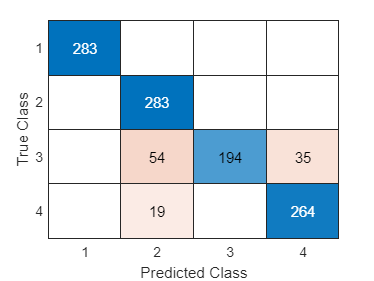

confusionchart(confusion_matrix)


%Η αποδοση μας ειναι πολυ καλη (περιπου 90,5%). Περισσοτερα λαθος
%αποτελεσματα παρατηρουμε στο φλαουτο, ενω λιγοτερα στην κιθαρα.
%Εχει μπερδεψει το φλαουτο 54 φορες με το τσελλο, και 35 φορες με την
%κιθαρα. Επισης εχει μπερδεψει 19 φορες την κιθαρα με το τσελλο.

%Askisi 1.d
clc; clear;

[x, Fs1]=audioread('piano_samples.wav');

[y, Fs2]=audioread('cello_samples.wav');
[z, Fs3]=audioread('flute_samples.wav');
[u, Fs4]=audioread('e_guitar_samples.wav');

mf1=mfcc(x, Fs1, "NumCoeffs", 29)%βαζουμε 29 γιατι αρχιζει να μετραει απο το 0

mf1 =   -14.9251  -33.1280    0.1322   -0.6195   -0.4154    0.2098   -0.2322   -0.2978   -0.4208   -0.1303    0.4042    0.2844    0.2718    0.0734   -0.0133    0.0476    0.3104   -0.2138    0.0612   -0.0830   -0.5254   -0.1728   -0.1599   -0.1986   -0.1879    0.0204   -0.0483    0.0353    0.0353    0.1067
  -14.4453  -31.2876    0.6067   -0.7883   -0.4825    0.2235   -0.1905    0.0070   -0.2978   -0.4551    0.1129    0.0364    0.0643    0.0887    0.0254    0.0313    0.2567   -0.0273   -0.1213    0.0081   -0.0856    0.1853   -0.0203   -0.1635    0.0212    0.1999   -0.0703   -0.0510   -0.0131    0.1009
   -6.4767  -23.5082    2.1136   -0.6468   -0.0270    0.4352    0.1802    0.0510    0.0706   -0.1811   -0.0451   -0.0175    0.0627    0.2616    0.2943    0.1885    0.0756   -0.0911   -0.1021   -0.0213    0.1168    0.2054    0.2230    0.0951    0.0028   -0.0834   -0.0807   -0.0787   -0.0335    0.0222
   -3.9538  -18.7442    3.1305   -0.0788    0.1518    0.3952    0.0140   -0.0334    0.1635 

mf2=mfcc(y, Fs2, "NumCoeffs", 29)

mf2 =     1.4849  -13.0102    4.4356   -0.7347    0.9538    0.1726    0.0133   -0.0183    0.5600    0.7346   -0.3136   -0.0338    0.2349    0.1257    0.1197    0.3146   -0.0910   -0.2688   -0.3408   -0.4764   -0.3524   -0.2793   -0.2037   -0.0969    0.1144    0.2653    0.0352   -0.0470    0.0237    0.1136
    1.5328  -13.0954    4.4829   -0.5550    0.8834    0.2882   -0.2024   -0.1218    0.6779    0.6644   -0.3722   -0.0313    0.2432    0.1262    0.1491    0.2961   -0.1593   -0.3017   -0.3249   -0.3811   -0.3401   -0.2787   -0.2063   -0.1867    0.0316    0.2912    0.0364   -0.1097   -0.0716    0.0589
    1.5193  -13.4952    4.7872   -0.7210    1.0176    0.1798   -0.3496   -0.1268    0.7751    0.8179   -0.4137   -0.0048    0.2154    0.1476    0.1616    0.3196   -0.2391   -0.3169   -0.1896   -0.4877   -0.2552   -0.4129   -0.3310   -0.2573   -0.0450    0.2988   -0.0321   -0.1326   -0.0354    0.0132
    1.6836  -13.3040    4.3197   -0.6066    0.8983   -0.0503   -0.2545   -0.0059    0.8707 

mf3=mfcc(z, Fs3, "NumCoeffs", 29)

mf3 =     0.0032  -17.9394    3.0359   -2.2210   -0.6171   -1.2527    0.0837    1.1595   -0.1011   -0.4800   -0.7682   -0.2627    0.9944    0.0280    0.1061    0.3321   -0.5207    0.0764    0.4434    0.0621    0.0703   -0.0787   -0.1414    0.0553   -0.2613    0.2131   -0.0674   -0.1975    0.4240   -0.0084
    1.4103  -15.2536    2.8972   -2.2952   -0.9689   -1.4155   -0.3890    0.7144   -0.1356   -0.2420   -1.0685   -0.7474    1.1358    0.1529   -0.0388    0.3074   -0.6797   -0.0049    0.7004    0.1213   -0.0473   -0.2056   -0.2758   -0.1166   -0.1294    0.6099   -0.3993   -0.5825    0.4161   -0.0082
    1.8485  -14.6430    3.2645   -2.4585   -0.9669   -1.0281   -0.3955    0.4595    0.1662   -0.1165   -1.1776   -0.9148    0.9719    0.2089    0.1385    0.4191   -0.7933   -0.1376    0.7916    0.1832    0.0676   -0.0999   -0.0997    0.0498   -0.1813    0.7668   -0.3946   -0.6395    0.2707   -0.0275
    1.8142  -14.8567    2.9813   -2.5524   -0.7809   -0.9142   -0.5674    0.3134    0.7973 

mf4=mfcc(u, Fs4, "NumCoeffs", 29)

mf4 =     1.6467  -14.7067    2.5551    0.4326    0.5260    0.5507    1.0052    0.0913   -0.8842   -0.9568   -0.0583   -0.4936   -0.1434   -0.9248   -0.9787   -0.0424    0.2686   -0.2689    0.2667   -0.0086   -0.5145    0.4241    0.3416   -0.2264    0.1143   -0.2164    0.2258    0.0893   -0.1498    0.1776
    2.7912  -11.9440    1.9675    0.4738    0.4593    0.3557    1.0450    0.3583   -0.6805   -0.9122   -0.1252   -0.6008   -0.3798   -1.3550   -1.2428   -0.1070    0.3344   -0.1374    0.2995   -0.0654   -0.5250    0.4833    0.5901   -0.1839    0.1088    0.2421    0.6224   -0.0251   -0.2669    0.1220
    3.3091  -10.5609    1.8600    0.2553    0.5571    0.0569    0.6857    0.4256   -0.1117   -0.8774   -0.3615   -0.5882   -0.1504   -1.3372   -1.2417   -0.1376    0.2038    0.3475    0.4384   -0.1194   -0.1445    0.5023    0.4980   -0.1213    0.0592    0.4646    0.5348   -0.2321   -0.2193    0.0403
    3.4917   -9.5203    2.0826   -0.2084    0.5896   -0.0923    0.9602    0.2942    0.0480 


tot1=mf1;
tot1(4001:end, :)=[]

tot1 =   -14.9251  -33.1280    0.1322   -0.6195   -0.4154    0.2098   -0.2322   -0.2978   -0.4208   -0.1303    0.4042    0.2844    0.2718    0.0734   -0.0133    0.0476    0.3104   -0.2138    0.0612   -0.0830   -0.5254   -0.1728   -0.1599   -0.1986   -0.1879    0.0204   -0.0483    0.0353    0.0353    0.1067
  -14.4453  -31.2876    0.6067   -0.7883   -0.4825    0.2235   -0.1905    0.0070   -0.2978   -0.4551    0.1129    0.0364    0.0643    0.0887    0.0254    0.0313    0.2567   -0.0273   -0.1213    0.0081   -0.0856    0.1853   -0.0203   -0.1635    0.0212    0.1999   -0.0703   -0.0510   -0.0131    0.1009
   -6.4767  -23.5082    2.1136   -0.6468   -0.0270    0.4352    0.1802    0.0510    0.0706   -0.1811   -0.0451   -0.0175    0.0627    0.2616    0.2943    0.1885    0.0756   -0.0911   -0.1021   -0.0213    0.1168    0.2054    0.2230    0.0951    0.0028   -0.0834   -0.0807   -0.0787   -0.0335    0.0222
   -3.9538  -18.7442    3.1305   -0.0788    0.1518    0.3952    0.0140   -0.0334    0.1635


tot2=mf2;
tot2(4001:end, :)=[]

tot2 =     1.4849  -13.0102    4.4356   -0.7347    0.9538    0.1726    0.0133   -0.0183    0.5600    0.7346   -0.3136   -0.0338    0.2349    0.1257    0.1197    0.3146   -0.0910   -0.2688   -0.3408   -0.4764   -0.3524   -0.2793   -0.2037   -0.0969    0.1144    0.2653    0.0352   -0.0470    0.0237    0.1136
    1.5328  -13.0954    4.4829   -0.5550    0.8834    0.2882   -0.2024   -0.1218    0.6779    0.6644   -0.3722   -0.0313    0.2432    0.1262    0.1491    0.2961   -0.1593   -0.3017   -0.3249   -0.3811   -0.3401   -0.2787   -0.2063   -0.1867    0.0316    0.2912    0.0364   -0.1097   -0.0716    0.0589
    1.5193  -13.4952    4.7872   -0.7210    1.0176    0.1798   -0.3496   -0.1268    0.7751    0.8179   -0.4137   -0.0048    0.2154    0.1476    0.1616    0.3196   -0.2391   -0.3169   -0.1896   -0.4877   -0.2552   -0.4129   -0.3310   -0.2573   -0.0450    0.2988   -0.0321   -0.1326   -0.0354    0.0132
    1.6836  -13.3040    4.3197   -0.6066    0.8983   -0.0503   -0.2545   -0.0059    0.8707


tot3=mf3;
tot3(4001:end, :)=[]

tot3 =     0.0032  -17.9394    3.0359   -2.2210   -0.6171   -1.2527    0.0837    1.1595   -0.1011   -0.4800   -0.7682   -0.2627    0.9944    0.0280    0.1061    0.3321   -0.5207    0.0764    0.4434    0.0621    0.0703   -0.0787   -0.1414    0.0553   -0.2613    0.2131   -0.0674   -0.1975    0.4240   -0.0084
    1.4103  -15.2536    2.8972   -2.2952   -0.9689   -1.4155   -0.3890    0.7144   -0.1356   -0.2420   -1.0685   -0.7474    1.1358    0.1529   -0.0388    0.3074   -0.6797   -0.0049    0.7004    0.1213   -0.0473   -0.2056   -0.2758   -0.1166   -0.1294    0.6099   -0.3993   -0.5825    0.4161   -0.0082
    1.8485  -14.6430    3.2645   -2.4585   -0.9669   -1.0281   -0.3955    0.4595    0.1662   -0.1165   -1.1776   -0.9148    0.9719    0.2089    0.1385    0.4191   -0.7933   -0.1376    0.7916    0.1832    0.0676   -0.0999   -0.0997    0.0498   -0.1813    0.7668   -0.3946   -0.6395    0.2707   -0.0275
    1.8142  -14.8567    2.9813   -2.5524   -0.7809   -0.9142   -0.5674    0.3134    0.7973


tot4=mf4;
tot4(4001:end, :)=[]

tot4 =     1.6467  -14.7067    2.5551    0.4326    0.5260    0.5507    1.0052    0.0913   -0.8842   -0.9568   -0.0583   -0.4936   -0.1434   -0.9248   -0.9787   -0.0424    0.2686   -0.2689    0.2667   -0.0086   -0.5145    0.4241    0.3416   -0.2264    0.1143   -0.2164    0.2258    0.0893   -0.1498    0.1776
    2.7912  -11.9440    1.9675    0.4738    0.4593    0.3557    1.0450    0.3583   -0.6805   -0.9122   -0.1252   -0.6008   -0.3798   -1.3550   -1.2428   -0.1070    0.3344   -0.1374    0.2995   -0.0654   -0.5250    0.4833    0.5901   -0.1839    0.1088    0.2421    0.6224   -0.0251   -0.2669    0.1220
    3.3091  -10.5609    1.8600    0.2553    0.5571    0.0569    0.6857    0.4256   -0.1117   -0.8774   -0.3615   -0.5882   -0.1504   -1.3372   -1.2417   -0.1376    0.2038    0.3475    0.4384   -0.1194   -0.1445    0.5023    0.4980   -0.1213    0.0592    0.4646    0.5348   -0.2321   -0.2193    0.0403
    3.4917   -9.5203    2.0826   -0.2084    0.5896   -0.0923    0.9602    0.2942    0.0480


m1=(1/4000)*sum(tot1); %για το πιανο
m1

m1 =    -0.1264  -17.6425    6.0594    0.0158    0.4693    0.0313   -0.3897   -0.1636    0.1757   -0.0344   -0.1351    0.0355    0.0776    0.0290    0.0981    0.0095   -0.0983   -0.0371   -0.0420   -0.2112   -0.1811   -0.0117    0.0411   -0.0014    0.1106    0.0507   -0.0912   -0.0607    0.0004    0.0151



m2=(1/4000)*sum(tot2);%για το τσελο
m2

m2 =     0.8472  -13.5940    4.1021   -0.9068    1.0832    0.2076    0.1499    0.2090    0.2509    0.2034   -0.0126    0.0421    0.0210    0.0373   -0.0004    0.1470    0.0935   -0.0118    0.0204   -0.0679   -0.1125   -0.0337    0.0478   -0.0388    0.0527    0.0457    0.0505   -0.0275    0.0193   -0.0099



m3=(1/4000)*sum(tot3);%για το φλαουτο
m3

m3 =     0.5834  -15.3590    3.3319   -1.4718   -0.3442   -0.6057   -0.3582   -0.4273   -0.0410   -0.2661   -0.1286   -0.1895   -0.1429   -0.0756    0.0337   -0.0273   -0.1056   -0.1560   -0.0188    0.0117    0.1137    0.0937    0.0412    0.0173   -0.1067    0.0627    0.0924   -0.0465   -0.0557   -0.0224



m4=(1/4000)*sum(tot4);%για την κιθαρα
m4

m4 =     3.0003   -8.6881    2.1250   -0.2462    0.2074   -0.2096    0.6376    0.4532    0.2798   -0.1564    0.2451   -0.1091    0.2306   -0.2573    0.0090    0.0573   -0.1627   -0.0492    0.1284   -0.0916    0.1399    0.1633    0.0290   -0.0603    0.2180    0.0787    0.0684   -0.1147    0.1440    0.0816



%πινακας συνδιασπορας
Si1=cov(tot1)%Για το πιανο

Si1 =     3.7245    5.2554   -0.1304   -0.5869    0.3784   -0.0686    0.0839    0.0245   -0.0126    0.1046    0.1519    0.2220    0.2602    0.1380    0.0345    0.0153    0.0439    0.0330   -0.0458   -0.0535   -0.0287   -0.0793    0.0035   -0.0715   -0.0058    0.1425    0.1520    0.0685   -0.0270    0.0505
    5.2554    8.4364   -0.5073   -0.9823    0.6603   -0.0437    0.1504    0.0602    0.0334    0.1897    0.2306    0.2962    0.3071    0.1575    0.0378    0.0114    0.0438    0.0415   -0.0628   -0.0905   -0.0565   -0.1529    0.0233   -0.0837   -0.0065    0.2068    0.2155    0.0857   -0.0430    0.1046
   -0.1304   -0.5073    0.5793   -0.0657    0.0417    0.0874   -0.0133    0.0539    0.0727    0.0295   -0.0225   -0.0749   -0.0982   -0.0915   -0.0547   -0.0044    0.0201   -0.0150   -0.0176    0.0178    0.0151    0.0569    0.0483    0.0141    0.0034    0.0055    0.0064   -0.0120    0.0010    0.0273
   -0.5869   -0.9823   -0.0657    0.4096   -0.1055    0.0378    0.0524    0.0240    0.0083 


Si2=cov(tot2)%Για το τσελο

Si2 =     1.2758    1.6886    0.0065   -0.1937    0.0595    0.0008   -0.0044   -0.0157    0.0137    0.0785   -0.0253    0.0660    0.0077   -0.0124    0.0101    0.0329    0.0079    0.0390    0.0771    0.0327   -0.0134   -0.0188   -0.0165   -0.0656   -0.0449    0.0064    0.0406    0.0134    0.0110   -0.0053
    1.6886    3.5238   -0.4558   -0.5377    0.0392   -0.0529    0.0663   -0.0983   -0.0183    0.0895   -0.0586    0.1455    0.0139   -0.0018    0.0201    0.0658    0.0774    0.0686    0.0753    0.0442   -0.0139   -0.0066   -0.0362   -0.1330   -0.1055   -0.0543   -0.0032   -0.0845   -0.1105   -0.0815
    0.0065   -0.4558    0.4565    0.0250    0.0238    0.0055   -0.0706    0.0319   -0.0094   -0.0060   -0.0309   -0.0490   -0.0303   -0.0181   -0.0137   -0.0167   -0.0340   -0.0363    0.0014   -0.0225   -0.0076   -0.0030    0.0339    0.0674    0.0681    0.0540    0.0137    0.0236    0.0459    0.0374
   -0.1937   -0.5377    0.0250    0.2423    0.0092    0.0172   -0.0222    0.0051    0.0037 


Si3=cov(tot3)%Για το φλαουτο

Si3 =     1.9519    1.5348   -0.1246   -0.4541   -0.3386   -0.3592   -0.1983    0.1338    0.1347    0.0604   -0.0490   -0.1095   -0.0397    0.0011    0.0147    0.1253    0.2442    0.2316    0.1311    0.0228   -0.0314    0.0342    0.0060    0.0437    0.0157    0.0714    0.0214   -0.0601   -0.0405   -0.0523
    1.5348    1.8755   -0.0634   -0.5174   -0.3298   -0.3678   -0.2379    0.0219    0.1419    0.0666   -0.0399   -0.1384   -0.0263   -0.0033    0.0072    0.1538    0.2152    0.2156    0.1541    0.0169   -0.0401    0.0144    0.0300    0.0729    0.0328    0.0367    0.0069   -0.0607   -0.0524   -0.0500
   -0.1246   -0.0634    0.6495    0.0762    0.1195    0.1462   -0.0409   -0.1809   -0.2409   -0.1656   -0.0966   -0.0937   -0.0768   -0.0224   -0.0108   -0.0497   -0.0604    0.0170    0.0402    0.0141   -0.0133   -0.0183    0.0183    0.0070   -0.0336   -0.0799    0.0476    0.0593   -0.0312   -0.0154
   -0.4541   -0.5174    0.0762    0.3585    0.1744    0.1388    0.0854   -0.0628   -0.0734 


Si4=cov(tot4)%Για την κιθαρα

Si4 =     0.4728    0.6659    0.1318   -0.0118   -0.0338   -0.0250    0.0002   -0.0083    0.0073   -0.0207   -0.0043   -0.0029   -0.0096   -0.0163   -0.0067   -0.0065   -0.0027   -0.0058    0.0067   -0.0064   -0.0029   -0.0092   -0.0026    0.0075    0.0122    0.0067    0.0015   -0.0073   -0.0025   -0.0034
    0.6659    3.0927   -0.4468   -0.1179   -0.2008   -0.0803   -0.0003   -0.0517    0.0005    0.0118    0.1051   -0.0293    0.0115   -0.1035   -0.0227    0.0628    0.0778   -0.0632   -0.1134   -0.0847    0.0206   -0.0446    0.0004    0.0297   -0.0280   -0.0606    0.0556   -0.0560   -0.0611    0.0072
    0.1318   -0.4468    1.0078    0.1163    0.1388    0.0160    0.0139    0.0346    0.0284    0.0428    0.0221    0.0600   -0.0659   -0.0719   -0.0176    0.0859    0.0495   -0.0119   -0.0466   -0.0039    0.0906    0.0856    0.0430    0.0527   -0.0326   -0.0352    0.0303    0.0151   -0.0290   -0.0046
   -0.0118   -0.1179    0.1163    0.1370    0.0182    0.0022   -0.0079   -0.0198   -0.0149 


ver1=mf1;
ver1(1:4000, :)=[]

ver1 =    -3.0506  -21.8298    5.7748    1.4266    0.2534    0.2989    0.0770    0.0631    0.3753    0.2644   -0.0123   -0.1284   -0.3040   -0.2824    0.1574    0.3838    0.1777   -0.1678   -0.2145   -0.1154    0.0738    0.1397    0.0138    0.0845    0.3192    0.3419    0.2101   -0.0011   -0.3294   -0.5994
   -3.0202  -22.4164    6.1612    1.4491    0.0344    0.3211    0.1755   -0.1071    0.4370    0.3313   -0.0648    0.0301   -0.3403   -0.2933    0.2710    0.5054    0.1369   -0.1985   -0.0533   -0.2659    0.0127    0.1907   -0.1276   -0.0423    0.1748    0.4183    0.2866    0.1668   -0.3339   -0.6916
   -3.0327  -22.2166    5.9915    1.4317    0.0863    0.1600    0.1677   -0.1290    0.5938    0.2764    0.0612   -0.1577   -0.3549   -0.2400    0.3868    0.5112    0.1754   -0.1895   -0.0876   -0.0825    0.0349    0.3893   -0.0187   -0.0326    0.1874    0.3886    0.1941    0.0320   -0.3397   -0.7138
   -3.1487  -22.5762    5.9713    1.5484    0.0480    0.2609    0.2555   -0.0783    0.6434


ver2=mf2;
ver2(1:4000, :)=[]

ver2 =     1.9080  -11.9703    3.8126   -0.9328    1.4799    0.6387   -0.1411    0.0182   -0.1291   -0.3755    0.0581    0.3359   -0.4985   -0.2024    0.1818    0.3751    0.2805    0.0723    0.0859    0.0741   -0.0128    0.0047    0.5765    0.1512    0.6354    0.5268    0.2424    0.0374   -0.1223   -0.6596
    1.8675  -11.8993    3.9678   -0.8632    1.5305    0.5535   -0.1031   -0.0243   -0.2053   -0.3468    0.3338    0.3864   -0.4034   -0.3523    0.1446    0.3246    0.3252    0.0608    0.1337    0.0395   -0.1185   -0.0323    0.5694    0.2933    0.6456    0.5073    0.3028   -0.0059   -0.3273   -0.7504
    1.8504  -11.8463    3.8280   -0.9080    1.6516    0.4783    0.0279   -0.1451   -0.2146   -0.3144    0.0786    0.3981   -0.3293   -0.3230    0.1700    0.2606    0.2590    0.0856    0.2632    0.1114   -0.0946   -0.1270    0.5769    0.2120    0.5394    0.4283    0.3212   -0.0057   -0.1111   -0.6189
    1.8413  -11.7379    3.5410   -0.9780    1.6530    0.4755   -0.0447   -0.2071   -0.2245


ver3=mf3;
ver3(1:4000, :)=[]

ver3 =    -0.1739  -14.9314    2.5416   -2.0432   -0.2529   -0.9691   -1.2297   -0.6872    0.0003    0.5858    0.6126   -0.1581   -0.2019    0.4769   -0.0364   -0.0850    0.7576   -0.0472   -0.8003   -0.0167   -0.0899   -0.1719    0.2933   -0.2457    0.2912    0.4181   -0.5957   -0.3084    0.2980   -0.0051
   -0.0368  -13.9070    2.4012   -1.2716   -0.2374   -0.4211   -0.8013   -0.5943    0.4611    0.4590    0.4264   -0.2864   -0.0759    0.3014    0.0651    0.0349    0.5477    0.1492   -0.6273   -0.0839   -0.2270   -0.3618    0.2265   -0.1998    0.1131    0.2135   -0.2344   -0.4124    0.2941   -0.1470
    0.2973  -13.2921    1.7937   -1.2129   -0.5002   -0.7379   -0.7791   -0.5454    0.7904    0.5997    0.4897   -0.3138   -0.0626    0.2063    0.3926    0.0904    0.2748    0.2876   -0.2533   -0.1688   -0.2857   -0.3928   -0.1085    0.0050    0.0745    0.1643   -0.1505   -0.2528   -0.0530   -0.3665
    0.7400  -13.6204    2.0299   -1.3955   -1.0722   -1.4624   -0.7953   -0.3356    0.5794


ver4=mf4;
ver4(1:4000, :)=[]

ver4 =     2.5447  -12.2839    3.1936   -0.2142    0.8570   -0.1493   -0.0914    0.6621    0.7782    0.1856    0.2674    0.2701   -0.1036   -0.1367    0.4575    0.3996    0.0041   -0.0236    0.1922   -0.0445    0.2159    0.3282    0.3099   -0.0633    0.0979   -0.2303    0.0527   -0.0696   -0.0421    0.0306
    1.9156  -13.0719    3.2237   -0.4267    0.6819   -0.0863   -0.0595    0.2930    0.3175   -0.2499   -0.0193    0.0828    0.2559   -0.1290    0.5019    0.4506    0.1388   -0.0154    0.0263   -0.1576   -0.1424    0.0064    0.0785   -0.1518   -0.0950   -0.0109    0.1223    0.2125    0.0864    0.1478
    1.3986  -13.2506    3.2600   -0.2008    0.5419   -0.1831    0.0342    0.2017    0.0840   -0.4174    0.0779    0.3165    0.1955   -0.2014    0.3165    0.4137   -0.0317   -0.1241   -0.0296   -0.2626   -0.0121    0.0148   -0.0031   -0.1332   -0.1290   -0.0086   -0.0483   -0.0389    0.2430    0.2036
    3.6940  -10.9309    4.1483   -0.7525    0.0615   -0.2038    0.5266    0.5669    0.3051


[rows1, cols1]=size(ver1)

rows1 = 283

cols1 = 30


%εχουμε ως input το πιανο
cell11=1;
cell12=0;
cell13=0;
cell14=0;

for f=1:rows1
p11=mvnpdf(ver1(f, :), m1, Si1);
p12=mvnpdf(ver1(f, :), m2, Si2);
p13=mvnpdf(ver1(f, :), m3, Si3);
p14=mvnpdf(ver1(f, :), m4, Si4);

    megisti_pithanotita=max([p11, p12, p13, p14]);
    if megisti_pithanotita==p11
        cell11=cell11+1;
        else if megisti_pithanotita==p12
                cell12=cell12+1;
            else if megisti_pithanotita==p13
                    cell13=cell13+1;
                else if megisti_pithanotita==p14
                        cell14=cell14+1;
                end
            end
        end
    end
end
win_percentage1=(cell11/283)*100

win_percentage1 = 98.9399


%εχουμε ως input το τσελο
cell21=1;
cell22=0;
cell23=0;
cell24=0;

for f=1:rows1
p21=mvnpdf(ver2(f, :), m1, Si1);
p22=mvnpdf(ver2(f, :), m2, Si2);
p23=mvnpdf(ver2(f, :), m3, Si3);
p24=mvnpdf(ver2(f, :), m4, Si4);

    megisti_pithanotita=max([p21, p22, p23, p24]);
    if megisti_pithanotita==p21
        cell21=cell21+1;
        else if megisti_pithanotita==p22
                cell22=cell22+1;
            else if megisti_pithanotita==p23
                    cell23=cell23+1;
                else if megisti_pithanotita==p24
                        cell24=cell24+1;
                end
            end
        end
    end
end
win_percentage2=(cell22/283)*100

win_percentage2 = 100


%εχουμε ως input το φλαουτο
cell31=1;
cell32=0;
cell33=0;
cell34=0;

for f=1:rows1
p31=mvnpdf(ver3(f, :), m1, Si1);
p32=mvnpdf(ver3(f, :), m2, Si2);
p33=mvnpdf(ver3(f, :), m3, Si3);
p34=mvnpdf(ver3(f, :), m4, Si4);

    megisti_pithanotita=max([p31, p32, p33, p34]);
    if megisti_pithanotita==p31
        cell31=cell31+1;
        else if megisti_pithanotita==p32
                cell32=cell32+1;
            else if megisti_pithanotita==p33
                cell33=cell33+1;
                else if megisti_pithanotita==p34
                    cell34=cell34+1;
                end
            end
        end
    end
end
win_percentage3=(cell33/283)*100

win_percentage3 = 99.6466


%εχουμε ως input την κιθαρα
cell41=1;
cell42=0;
cell43=0;
cell44=0;

for f=1:rows1
p41=mvnpdf(ver4(f, :), m1, Si1);
p42=mvnpdf(ver4(f, :), m2, Si2);
p43=mvnpdf(ver4(f, :), m3, Si3);
p44=mvnpdf(ver4(f, :), m4, Si4);

    megisti_pithanotita=max([p41, p42, p43, p44]);
    if megisti_pithanotita==p41
        cell41=cell41+1;
        else if megisti_pithanotita==p42
                cell42=cell42+1;
            else if megisti_pithanotita==p43
                    cell43=cell43+1;
                else if megisti_pithanotita==p44
                        cell44=cell44+1;
                end
            end
        end
    end
end
win_percentage4=(cell44/283)*100

win_percentage4 = 99.2933

total_win_percentage=((cell11+cell22+cell33+cell44)/(4*283))*100

total_win_percentage = 99.4700


%confusion matrix
confusion_matrix=[cell11 cell12 cell13 cell14;cell21 cell22 cell23 cell24; cell31 cell32 cell33 cell34; cell41 cell42 cell43 cell44]

confusion_matrix =    280     3     1     0
     1   283     0     0
     2     0   282     0
     1     2     0   281


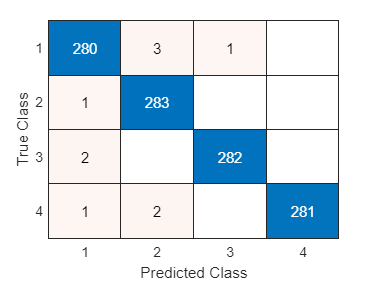

confusionchart(confusion_matrix)


%Η αποδοση μας ειναι καλυτερη σε συγκριση με την προηγουμενη μεθοδο αναγνωρισης
%(απο περιπου 90,5% στο περιπου 99.5). Παρατηρουμε και στα τεσσερα οργανα
%ελαχιστα λαθη, τα οποια ομως ειναι συνολικα πολυ λιγοτερα συγκριτικα με
%τα προηγουμενα.

%Askisi 1.e (euclideian distance)
clc; clear;

[x, Fs1]=audioread('piano_samples.wav');
[y, Fs2]=audioread('cello_samples.wav');
[z, Fs3]=audioread('flute_samples.wav');
[u, Fs4]=audioread('e_guitar_samples.wav');

X=frame_wind(x, 256, 0.25); %πιανο
Y=frame_wind(y, 256, 0.25); %τσελλο
Z=frame_wind(z, 256, 0.25); %φλαουτο
U=frame_wind(u, 256, 0.25); %κιθαρα


x_lpc=lpc(X,29);
y_lpc=lpc(Y,29);
z_lpc=lpc(Z,29);
u_lpc=lpc(U,29);

x_lpc(14794:end, :)=[]

x_lpc =     1.0000    0.4859   -0.2770   -0.0691   -0.0512   -0.4890   -0.2186   -0.0605   -0.1346   -0.0175    0.2882    0.0799   -0.0339   -0.1159   -0.2129   -0.1889    0.0151   -0.1431   -0.0312    0.0217    0.0798    0.0587    0.0931   -0.0570    0.0369    0.0668   -0.0762   -0.0483    0.1225   -0.0894
    1.0000    0.6102   -0.2502   -0.1022    0.0633   -0.3067   -0.3002   -0.0669   -0.0655   -0.1889   -0.0466    0.0582   -0.0895   -0.2162   -0.0935   -0.0013   -0.0901   -0.2576   -0.1427   -0.0209    0.0405    0.0566    0.0843   -0.0013    0.0613    0.0881    0.0373    0.0547    0.1312   -0.0029
    1.0000    0.4584   -0.2570   -0.0808   -0.1172   -0.2728   -0.1888    0.0622   -0.0769   -0.2362   -0.0508    0.1616   -0.0781   -0.1369    0.0441    0.0144   -0.1042   -0.1990    0.0155    0.0666   -0.0199    0.0460    0.0770   -0.1545   -0.1972    0.0993    0.0886   -0.0250    0.0490    0.0545
    1.0000    0.2673   -0.2977   -0.2550   -0.1918   -0.0543    0.1260    0.0895   -0.042

y_lpc(14794:end, :)=[]

y_lpc =     1.0000   -3.0016    3.7015   -2.5564    1.4551   -1.0956    0.6360   -0.2230    0.6025   -1.0060    0.5957   -0.2783    0.6875   -0.9094    0.5299   -0.3288    0.5774   -0.7365    0.8592   -1.2390    1.4118   -1.1735    0.9289   -0.8893    0.8678   -0.6669    0.3146    0.0719   -0.2337    0.1105
    1.0000   -2.9294    3.4226   -2.2080    1.2708   -0.9922    0.5581   -0.2880    0.7652   -1.2493    1.0387   -0.8283    0.9641   -0.7792    0.3677   -0.3103    0.5074   -0.5556    0.6544   -1.0129    1.0763   -0.8067    0.7552   -0.8403    0.7560   -0.6008    0.4150   -0.1993    0.0852   -0.0282
    1.0000   -3.0268    3.7825   -2.8576    2.1835   -2.1270    1.6992   -1.2825    1.6715   -1.9907    1.4724   -1.1191    1.4306   -1.4999    1.1469   -0.9807    1.0563   -0.9591    0.8208   -0.9911    1.1063   -1.0120    1.0571   -1.2286    1.2157   -0.9488    0.5812   -0.2366    0.0403    0.0039
    1.0000   -3.0085    3.7528   -2.9034    2.2898   -2.1519    1.7375   -1.4735    1.896

z_lpc(14794:end, :)=[]

z_lpc =     1.0000    0.3915   -0.3135    0.0100    0.1083   -0.3501   -0.1450    0.1446   -0.0287   -0.2169   -0.0857   -0.2550   -0.1421   -0.1104   -0.0794    0.1102    0.0618   -0.1051    0.0468   -0.0162   -0.2085    0.0517    0.1968    0.0115    0.1198    0.1510   -0.0413   -0.3345   -0.0187    0.0800
    1.0000    0.3341   -0.4605   -0.1149    0.0448   -0.2319   -0.0544    0.1371   -0.0052   -0.0765   -0.1004   -0.1789   -0.0994   -0.1476   -0.0275    0.0848    0.0151   -0.0333   -0.0658   -0.1291   -0.0633    0.0053    0.1568    0.1341    0.0596    0.0463    0.0649   -0.1618   -0.0509   -0.0297
    1.0000    0.1487   -0.7482   -0.4157    0.1720    0.2162    0.0111    0.0400    0.1135    0.0146   -0.1823   -0.2298    0.0315    0.1199    0.0484   -0.0709   -0.0048    0.1044   -0.0725   -0.2324    0.0200    0.1835    0.0702   -0.1871   -0.0648    0.0712    0.1237   -0.1937   -0.0627    0.0450
    1.0000   -1.6520   -0.0419    1.3359   -0.0507   -0.6773   -0.1263    0.2646    0.174

u_lpc(14794:end, :)=[]

u_lpc =     1.0000    0.2847   -0.4094   -0.1870   -0.0848   -0.0026    0.0340   -0.1748   -0.0035    0.0453   -0.1188   -0.0260   -0.0107   -0.0089    0.0533   -0.1418   -0.1565   -0.0583   -0.0135    0.1685    0.1131    0.0647    0.0992   -0.0733   -0.1963    0.0970   -0.0107   -0.0211   -0.0969   -0.1086
    1.0000    0.4833   -0.1955   -0.2166   -0.1649   -0.1001   -0.0932   -0.0251    0.0387   -0.0625   -0.1341   -0.1670   -0.1271   -0.1664   -0.0342    0.0066    0.0129   -0.1410   -0.0973    0.1084    0.0169    0.0505    0.1983    0.0961   -0.0770   -0.1119    0.0212    0.0208    0.0024   -0.0927
    1.0000   -0.0206   -0.6253   -0.2503   -0.0767    0.1386   -0.0842   -0.0273   -0.0411    0.0717    0.2281    0.0326   -0.0545   -0.0123   -0.0467    0.0128   -0.1138   -0.0858   -0.0013    0.0734    0.1147    0.0062   -0.0561   -0.0992    0.0339   -0.1060    0.0563    0.0873   -0.0485   -0.0578
    1.0000   -2.1182    1.7635   -0.8834    0.2423    0.3830   -0.6941    0.6247   -0.762


%αντι για τους συντελεστες mf
tot1=x_lpc;
tot1(14511:end, :)=[]

tot1 =     1.0000    0.4859   -0.2770   -0.0691   -0.0512   -0.4890   -0.2186   -0.0605   -0.1346   -0.0175    0.2882    0.0799   -0.0339   -0.1159   -0.2129   -0.1889    0.0151   -0.1431   -0.0312    0.0217    0.0798    0.0587    0.0931   -0.0570    0.0369    0.0668   -0.0762   -0.0483    0.1225   -0.0894
    1.0000    0.6102   -0.2502   -0.1022    0.0633   -0.3067   -0.3002   -0.0669   -0.0655   -0.1889   -0.0466    0.0582   -0.0895   -0.2162   -0.0935   -0.0013   -0.0901   -0.2576   -0.1427   -0.0209    0.0405    0.0566    0.0843   -0.0013    0.0613    0.0881    0.0373    0.0547    0.1312   -0.0029
    1.0000    0.4584   -0.2570   -0.0808   -0.1172   -0.2728   -0.1888    0.0622   -0.0769   -0.2362   -0.0508    0.1616   -0.0781   -0.1369    0.0441    0.0144   -0.1042   -0.1990    0.0155    0.0666   -0.0199    0.0460    0.0770   -0.1545   -0.1972    0.0993    0.0886   -0.0250    0.0490    0.0545
    1.0000    0.2673   -0.2977   -0.2550   -0.1918   -0.0543    0.1260    0.0895   -0.0421


tot2=y_lpc;
tot2(14511:end, :)=[]

tot2 =     1.0000   -3.0016    3.7015   -2.5564    1.4551   -1.0956    0.6360   -0.2230    0.6025   -1.0060    0.5957   -0.2783    0.6875   -0.9094    0.5299   -0.3288    0.5774   -0.7365    0.8592   -1.2390    1.4118   -1.1735    0.9289   -0.8893    0.8678   -0.6669    0.3146    0.0719   -0.2337    0.1105
    1.0000   -2.9294    3.4226   -2.2080    1.2708   -0.9922    0.5581   -0.2880    0.7652   -1.2493    1.0387   -0.8283    0.9641   -0.7792    0.3677   -0.3103    0.5074   -0.5556    0.6544   -1.0129    1.0763   -0.8067    0.7552   -0.8403    0.7560   -0.6008    0.4150   -0.1993    0.0852   -0.0282
    1.0000   -3.0268    3.7825   -2.8576    2.1835   -2.1270    1.6992   -1.2825    1.6715   -1.9907    1.4724   -1.1191    1.4306   -1.4999    1.1469   -0.9807    1.0563   -0.9591    0.8208   -0.9911    1.1063   -1.0120    1.0571   -1.2286    1.2157   -0.9488    0.5812   -0.2366    0.0403    0.0039
    1.0000   -3.0085    3.7528   -2.9034    2.2898   -2.1519    1.7375   -1.4735    1.8969


tot3=z_lpc;
tot3(14511:end, :)=[]

tot3 =     1.0000    0.3915   -0.3135    0.0100    0.1083   -0.3501   -0.1450    0.1446   -0.0287   -0.2169   -0.0857   -0.2550   -0.1421   -0.1104   -0.0794    0.1102    0.0618   -0.1051    0.0468   -0.0162   -0.2085    0.0517    0.1968    0.0115    0.1198    0.1510   -0.0413   -0.3345   -0.0187    0.0800
    1.0000    0.3341   -0.4605   -0.1149    0.0448   -0.2319   -0.0544    0.1371   -0.0052   -0.0765   -0.1004   -0.1789   -0.0994   -0.1476   -0.0275    0.0848    0.0151   -0.0333   -0.0658   -0.1291   -0.0633    0.0053    0.1568    0.1341    0.0596    0.0463    0.0649   -0.1618   -0.0509   -0.0297
    1.0000    0.1487   -0.7482   -0.4157    0.1720    0.2162    0.0111    0.0400    0.1135    0.0146   -0.1823   -0.2298    0.0315    0.1199    0.0484   -0.0709   -0.0048    0.1044   -0.0725   -0.2324    0.0200    0.1835    0.0702   -0.1871   -0.0648    0.0712    0.1237   -0.1937   -0.0627    0.0450
    1.0000   -1.6520   -0.0419    1.3359   -0.0507   -0.6773   -0.1263    0.2646    0.1745


tot4=u_lpc;
tot4(14511:end, :)=[]

tot4 =     1.0000    0.2847   -0.4094   -0.1870   -0.0848   -0.0026    0.0340   -0.1748   -0.0035    0.0453   -0.1188   -0.0260   -0.0107   -0.0089    0.0533   -0.1418   -0.1565   -0.0583   -0.0135    0.1685    0.1131    0.0647    0.0992   -0.0733   -0.1963    0.0970   -0.0107   -0.0211   -0.0969   -0.1086
    1.0000    0.4833   -0.1955   -0.2166   -0.1649   -0.1001   -0.0932   -0.0251    0.0387   -0.0625   -0.1341   -0.1670   -0.1271   -0.1664   -0.0342    0.0066    0.0129   -0.1410   -0.0973    0.1084    0.0169    0.0505    0.1983    0.0961   -0.0770   -0.1119    0.0212    0.0208    0.0024   -0.0927
    1.0000   -0.0206   -0.6253   -0.2503   -0.0767    0.1386   -0.0842   -0.0273   -0.0411    0.0717    0.2281    0.0326   -0.0545   -0.0123   -0.0467    0.0128   -0.1138   -0.0858   -0.0013    0.0734    0.1147    0.0062   -0.0561   -0.0992    0.0339   -0.1060    0.0563    0.0873   -0.0485   -0.0578
    1.0000   -2.1182    1.7635   -0.8834    0.2423    0.3830   -0.6941    0.6247   -0.7629


m1=mean(tot1); %για το πιανο
m1

m1 =     1.0000   -3.2573    4.3421   -3.5955    2.9031   -2.4471    1.6405   -0.9627    0.7701   -0.8979    1.0890   -1.0495    0.8475   -0.6651    0.4679   -0.3450    0.2981   -0.2448    0.2120   -0.2017    0.2201   -0.2397    0.2211   -0.1867    0.1483   -0.0678   -0.0413    0.0942   -0.0663    0.0192



m2=mean(tot2);%για το τσελο
m2

m2 =     1.0000   -2.6920    2.8399   -1.6462    1.1969   -1.5126    1.4519   -1.2369    1.3607   -1.4917    1.3793   -1.3044    1.3968   -1.4117    1.3077   -1.2725    1.3045   -1.2167    1.0392   -0.9742    0.9941   -0.9420    0.8031   -0.6787    0.6119   -0.5566    0.5063   -0.3971    0.1993   -0.0400



m3=mean(tot3);%για το φλαουτο
m3

m3 =     1.0000   -2.3895    2.0666   -0.6916    0.2150   -0.5529    0.9418   -0.9979    0.8209   -0.7283    0.8504   -0.9543    0.9582   -0.8597    0.7864   -0.7571    0.7593   -0.7601    0.7585   -0.6809    0.5679   -0.5056    0.5114   -0.4798    0.4066   -0.3668    0.3775   -0.3473    0.2200   -0.0634



m4=mean(tot4);%για την κιθαρα
m4

m4 =     1.0000   -2.6035    3.6901   -4.0087    3.6655   -3.2392    3.1669   -3.3431    3.4880   -3.4582    3.4088   -3.3459    3.3734   -3.5036    3.5469   -3.4990    3.3035   -2.9185    2.4652   -2.1429    1.9944   -1.9417    1.8391   -1.6033    1.3150   -0.9791    0.6691   -0.4036    0.1676   -0.0249



ver1=x_lpc;
ver1(1:14510, :)=[]

ver1 =     1.0000   -1.2712    0.0318   -0.1839    0.1404   -0.2500    0.8590   -0.2344    0.2201   -0.0990    0.0591   -0.3896    0.3844   -0.5332    0.2307   -0.2255    0.2056   -0.2132    0.5162   -0.3645    0.2960   -0.0478   -0.0541   -0.1193    0.2494   -0.3145   -0.0028   -0.0292    0.2637   -0.1211
    1.0000   -1.3460    0.0487   -0.1979    0.3884   -0.4053    1.0386   -0.4602    0.2194   -0.2574    0.1095   -0.1987    0.3744   -0.5609    0.2701   -0.2810    0.1857   -0.3029    0.8313   -0.6126    0.3427   -0.2409    0.2111   -0.2084    0.2476   -0.3170    0.1689   -0.1393    0.0425    0.0532
    1.0000   -1.3379   -0.0486   -0.1171    0.4136   -0.3512    1.1268   -0.7709    0.3628   -0.3221    0.3991   -0.5948    0.6979   -0.8661    0.3944   -0.3103    0.3541   -0.3752    0.9653   -0.7149    0.0956   -0.1425    0.2681   -0.2147    0.4306   -0.3746   -0.0348   -0.0703    0.1417   -0.0008
    1.0000   -1.3621    0.0343   -0.0778    0.0696    0.0791    0.9535   -0.8816    0.4375


ver2=y_lpc;
ver2(1:14510, :)=[]

ver2 =     1.0000   -2.6699    2.9290   -2.0896    1.8915   -1.9362    1.3172   -0.6955    0.7690   -1.0060    0.7670   -0.4793    0.5714   -0.6457    0.6947   -1.0409    1.3425   -1.5448    1.8206   -1.8519    1.5417   -1.1955    1.0116   -0.7967    0.3525   -0.0699    0.1449   -0.1386   -0.0126    0.0420
    1.0000   -2.6290    2.6341   -1.3888    1.0433   -1.3467    0.9657   -0.3183    0.2839   -0.5430    0.4452   -0.3369    0.5781   -0.8329    0.9993   -1.0079    0.7231   -0.6894    1.0320   -1.0739    0.8683   -0.8704    0.9597   -0.7949    0.4762   -0.3690    0.3563   -0.1284   -0.0509    0.0277
    1.0000   -2.5908    2.6662   -1.6567    1.3397   -1.4641    1.0971   -0.5976    0.5185   -0.5393    0.3186   -0.3594    0.6617   -0.7355    0.7587   -0.9087    0.9615   -0.9230    0.8397   -0.7972    0.9290   -0.9714    0.7696   -0.5178    0.3270   -0.1434    0.0697   -0.0936    0.1366   -0.0874
    1.0000   -2.5999    2.6003   -1.4162    1.0384   -1.2182    0.9383   -0.6598    0.8489


ver3=z_lpc;
ver3(1:14510, :)=[]

ver3 =     1.0000   -2.4248    2.1972   -0.9669    0.8066   -1.1430    1.0412   -0.6999    0.6802   -1.0153    1.1256   -0.8133    0.6571   -0.8237    1.0564   -0.8222    0.5742   -0.6463    0.4202   -0.2564    0.7955   -0.9828    0.5462   -0.2232    0.3210   -0.4126    0.0118    0.5640   -0.5364    0.1517
    1.0000   -2.4925    2.3783   -1.0699    0.6153   -0.7428    0.6642   -0.5234    0.7809   -1.3327    1.4714   -0.9046    0.4088   -0.5117    0.9530   -0.8987    0.6192   -0.5375    0.1555    0.2415    0.1136   -0.4248    0.2868   -0.1435    0.2167   -0.2057   -0.1743    0.6586   -0.5964    0.1840
    1.0000   -2.6192    2.9359   -2.0908    1.6390   -1.5270    1.4361   -1.3420    1.5171   -2.0377    2.2902   -1.9426    1.6003   -1.6546    1.9117   -1.6751    1.3185   -1.2859    1.0289   -0.6945    0.8291   -0.7981    0.4581   -0.1294    0.0912   -0.2872    0.2438    0.0982   -0.1906    0.0524
    1.0000   -2.4388    2.4640   -1.6236    1.4073   -1.3648    1.3247   -1.4527    1.6598


ver4=u_lpc;
ver4(1:14510, :)=[]

ver4 =     1.0000   -2.3139    2.9009   -2.9263    2.4885   -2.1240    1.9904   -1.8953    1.7932   -1.5355    1.5175   -1.6000    1.6836   -1.7789    1.6782   -1.5283    1.3413   -1.0776    0.8370   -0.8201    1.0061   -1.2149    1.3415   -1.3895    1.2730   -0.9142    0.5108   -0.2270   -0.0263    0.0694
    1.0000   -2.3706    3.0505   -3.0833    2.5205   -1.9159    1.5346   -1.2350    1.0535   -0.9987    1.3276   -1.8072    2.2434   -2.4258    2.2314   -1.9687    1.6737   -1.1663    0.4801    0.0284   -0.1461   -0.2318    0.8122   -1.2264    1.4454   -1.3610    1.0063   -0.6311    0.2722   -0.0505
    1.0000   -2.4867    3.2685   -3.2665    2.5275   -1.7574    1.4354   -1.2098    1.0207   -1.0014    1.3957   -2.0192    2.6158   -2.8917    2.5525   -2.0074    1.5162   -0.9339    0.2246    0.3158   -0.3586   -0.1417    0.7785   -1.1586    1.2415   -1.0909    0.8358   -0.5682    0.2631   -0.0478
    1.0000   -2.3841    3.0100   -2.9591    2.2781   -1.7022    1.6635   -1.6919    1.6536


[rows1, cols1]=size(ver1)

rows1 = 283

cols1 = 30


cell11=0;
cell12=0;
cell13=0;
cell14=0;

%Για το πιανο
for f=1:rows1
d11=pdist2(ver1(f, :), m1);
d12=pdist2(ver1(f, :), m2);
d13=pdist2(ver1(f, :), m3);
d14=pdist2(ver1(f, :), m4);

elaxisti_apostasi=min([d11, d12, d13, d14]);
    if elaxisti_apostasi==d11
        cell11=cell11+1;
        else if elaxisti_apostasi==d12
                cell12=cell12+1;
            else if elaxisti_apostasi==d13
                    cell13=cell13+1;
                else if elaxisti_apostasi==d14
                        cell14=cell14+1;
                end
            end
        end
    end
end
win_percentage1=(cell11/283)*100

win_percentage1 = 0


%Για το τσελλο
cell21=0;
cell22=0;
cell23=0;
cell24=0;

for f=1:rows1
d21=pdist2(ver2(f, :), m1);
d22=pdist2(ver2(f, :), m2);
d23=pdist2(ver2(f, :), m3);
d24=pdist2(ver2(f, :), m4);

elaxisti_apostasi=min([d21, d22, d23, d24]);
    if elaxisti_apostasi==d21
        cell21=cell21+1;
        else if elaxisti_apostasi==d22
                cell22=cell22+1;
            else if elaxisti_apostasi==d23
                    cell23=cell23+1;
                else if elaxisti_apostasi==d24
                        cell24=cell24+1;
                end
            end
        end
    end
end
win_percentage2=(cell22/283)*100

win_percentage2 = 51.5901


cell31=0;
cell32=0;
cell33=0;
cell34=0;

%Για το φλαουτο
for f=1:rows1
d31=pdist2(ver3(f, :), m1);
d32=pdist2(ver3(f, :), m2);
d33=pdist2(ver3(f, :), m3);
d34=pdist2(ver3(f, :), m4);

elaxisti_apostasi=min([d31, d32, d33, d34]);
    if elaxisti_apostasi==d31
        cell31=cell31+1;
        else if elaxisti_apostasi==d32
                cell32=cell32+1;
            else if elaxisti_apostasi==d33
                    cell33=cell33+1;
                else if elaxisti_apostasi==d34
                        cell34=cell34+1;
                end
            end
        end
    end
end
win_percentage3=(cell33/283)*100

win_percentage3 = 81.9788


%Για την ηλεκτρικη κιθαρα
cell41=0;
cell42=0;
cell43=0;
cell44=0;

for f=1:rows1
d41=pdist2(ver4(f, :), m1);
d42=pdist2(ver4(f, :), m2);
d43=pdist2(ver4(f, :), m3);
d44=pdist2(ver4(f, :), m4);

elaxisti_apostasi=min([d41, d42, d43, d44]);
    if elaxisti_apostasi==d41
        cell41=cell41+1;
        else if elaxisti_apostasi==d42
                cell42=cell42+1;
            else if elaxisti_apostasi==d43
                    cell43=cell43+1;
                else if elaxisti_apostasi==d44
                        cell44=cell44+1;
                end
            end
        end
    end
end
win_percentage4=(cell44/283)*100

win_percentage4 = 66.4311

total_win_percentage=((cell11+cell22+cell33+cell44)/(4*283))*100

total_win_percentage = 50


%confusion matrix
confusion_matrix=[cell11 cell12 cell13 cell14;cell21 cell22 cell23 cell24; cell31 cell32 cell33 cell34; cell41 cell42 cell43 cell44]

confusion_matrix =      0     0   283     0
     4   146   119    14
     0    47   232     4
     2    76    17   188


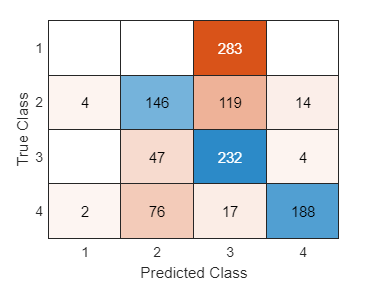

confusionchart(confusion_matrix)

%Askisi 1.e (gaussian)
clc; clear;

[x, Fs1]=audioread('piano_samples.wav');
[y, Fs2]=audioread('cello_samples.wav');
[z, Fs3]=audioread('flute_samples.wav');
[u, Fs4]=audioread('e_guitar_samples.wav');

X=frame_wind(x, 256, 0.25); %πιανο
Y=frame_wind(y, 256, 0.25); %τσελλο
Z=frame_wind(z, 256, 0.25); %φλαουτο
U=frame_wind(u, 256, 0.25); %κιθαρα


x_lpc=lpc(X,29);
y_lpc=lpc(Y,29);
z_lpc=lpc(Z,29);
u_lpc=lpc(U,29);

x_lpc(14794:end, :)=[]

x_lpc =     1.0000    0.4859   -0.2770   -0.0691   -0.0512   -0.4890   -0.2186   -0.0605   -0.1346   -0.0175    0.2882    0.0799   -0.0339   -0.1159   -0.2129   -0.1889    0.0151   -0.1431   -0.0312    0.0217    0.0798    0.0587    0.0931   -0.0570    0.0369    0.0668   -0.0762   -0.0483    0.1225   -0.0894
    1.0000    0.6102   -0.2502   -0.1022    0.0633   -0.3067   -0.3002   -0.0669   -0.0655   -0.1889   -0.0466    0.0582   -0.0895   -0.2162   -0.0935   -0.0013   -0.0901   -0.2576   -0.1427   -0.0209    0.0405    0.0566    0.0843   -0.0013    0.0613    0.0881    0.0373    0.0547    0.1312   -0.0029
    1.0000    0.4584   -0.2570   -0.0808   -0.1172   -0.2728   -0.1888    0.0622   -0.0769   -0.2362   -0.0508    0.1616   -0.0781   -0.1369    0.0441    0.0144   -0.1042   -0.1990    0.0155    0.0666   -0.0199    0.0460    0.0770   -0.1545   -0.1972    0.0993    0.0886   -0.0250    0.0490    0.0545
    1.0000    0.2673   -0.2977   -0.2550   -0.1918   -0.0543    0.1260    0.0895   -0.042

y_lpc(14794:end, :)=[]

y_lpc =     1.0000   -3.0016    3.7015   -2.5564    1.4551   -1.0956    0.6360   -0.2230    0.6025   -1.0060    0.5957   -0.2783    0.6875   -0.9094    0.5299   -0.3288    0.5774   -0.7365    0.8592   -1.2390    1.4118   -1.1735    0.9289   -0.8893    0.8678   -0.6669    0.3146    0.0719   -0.2337    0.1105
    1.0000   -2.9294    3.4226   -2.2080    1.2708   -0.9922    0.5581   -0.2880    0.7652   -1.2493    1.0387   -0.8283    0.9641   -0.7792    0.3677   -0.3103    0.5074   -0.5556    0.6544   -1.0129    1.0763   -0.8067    0.7552   -0.8403    0.7560   -0.6008    0.4150   -0.1993    0.0852   -0.0282
    1.0000   -3.0268    3.7825   -2.8576    2.1835   -2.1270    1.6992   -1.2825    1.6715   -1.9907    1.4724   -1.1191    1.4306   -1.4999    1.1469   -0.9807    1.0563   -0.9591    0.8208   -0.9911    1.1063   -1.0120    1.0571   -1.2286    1.2157   -0.9488    0.5812   -0.2366    0.0403    0.0039
    1.0000   -3.0085    3.7528   -2.9034    2.2898   -2.1519    1.7375   -1.4735    1.896

z_lpc(14794:end, :)=[]

z_lpc =     1.0000    0.3915   -0.3135    0.0100    0.1083   -0.3501   -0.1450    0.1446   -0.0287   -0.2169   -0.0857   -0.2550   -0.1421   -0.1104   -0.0794    0.1102    0.0618   -0.1051    0.0468   -0.0162   -0.2085    0.0517    0.1968    0.0115    0.1198    0.1510   -0.0413   -0.3345   -0.0187    0.0800
    1.0000    0.3341   -0.4605   -0.1149    0.0448   -0.2319   -0.0544    0.1371   -0.0052   -0.0765   -0.1004   -0.1789   -0.0994   -0.1476   -0.0275    0.0848    0.0151   -0.0333   -0.0658   -0.1291   -0.0633    0.0053    0.1568    0.1341    0.0596    0.0463    0.0649   -0.1618   -0.0509   -0.0297
    1.0000    0.1487   -0.7482   -0.4157    0.1720    0.2162    0.0111    0.0400    0.1135    0.0146   -0.1823   -0.2298    0.0315    0.1199    0.0484   -0.0709   -0.0048    0.1044   -0.0725   -0.2324    0.0200    0.1835    0.0702   -0.1871   -0.0648    0.0712    0.1237   -0.1937   -0.0627    0.0450
    1.0000   -1.6520   -0.0419    1.3359   -0.0507   -0.6773   -0.1263    0.2646    0.174

u_lpc(14794:end, :)=[]

u_lpc =     1.0000    0.2847   -0.4094   -0.1870   -0.0848   -0.0026    0.0340   -0.1748   -0.0035    0.0453   -0.1188   -0.0260   -0.0107   -0.0089    0.0533   -0.1418   -0.1565   -0.0583   -0.0135    0.1685    0.1131    0.0647    0.0992   -0.0733   -0.1963    0.0970   -0.0107   -0.0211   -0.0969   -0.1086
    1.0000    0.4833   -0.1955   -0.2166   -0.1649   -0.1001   -0.0932   -0.0251    0.0387   -0.0625   -0.1341   -0.1670   -0.1271   -0.1664   -0.0342    0.0066    0.0129   -0.1410   -0.0973    0.1084    0.0169    0.0505    0.1983    0.0961   -0.0770   -0.1119    0.0212    0.0208    0.0024   -0.0927
    1.0000   -0.0206   -0.6253   -0.2503   -0.0767    0.1386   -0.0842   -0.0273   -0.0411    0.0717    0.2281    0.0326   -0.0545   -0.0123   -0.0467    0.0128   -0.1138   -0.0858   -0.0013    0.0734    0.1147    0.0062   -0.0561   -0.0992    0.0339   -0.1060    0.0563    0.0873   -0.0485   -0.0578
    1.0000   -2.1182    1.7635   -0.8834    0.2423    0.3830   -0.6941    0.6247   -0.762


%αντι για τους συντελεστες mf
tot1=x_lpc;
tot1(14511:end, :)=[]

tot1 =     1.0000    0.4859   -0.2770   -0.0691   -0.0512   -0.4890   -0.2186   -0.0605   -0.1346   -0.0175    0.2882    0.0799   -0.0339   -0.1159   -0.2129   -0.1889    0.0151   -0.1431   -0.0312    0.0217    0.0798    0.0587    0.0931   -0.0570    0.0369    0.0668   -0.0762   -0.0483    0.1225   -0.0894
    1.0000    0.6102   -0.2502   -0.1022    0.0633   -0.3067   -0.3002   -0.0669   -0.0655   -0.1889   -0.0466    0.0582   -0.0895   -0.2162   -0.0935   -0.0013   -0.0901   -0.2576   -0.1427   -0.0209    0.0405    0.0566    0.0843   -0.0013    0.0613    0.0881    0.0373    0.0547    0.1312   -0.0029
    1.0000    0.4584   -0.2570   -0.0808   -0.1172   -0.2728   -0.1888    0.0622   -0.0769   -0.2362   -0.0508    0.1616   -0.0781   -0.1369    0.0441    0.0144   -0.1042   -0.1990    0.0155    0.0666   -0.0199    0.0460    0.0770   -0.1545   -0.1972    0.0993    0.0886   -0.0250    0.0490    0.0545
    1.0000    0.2673   -0.2977   -0.2550   -0.1918   -0.0543    0.1260    0.0895   -0.0421


tot2=y_lpc;
tot2(14511:end, :)=[]

tot2 =     1.0000   -3.0016    3.7015   -2.5564    1.4551   -1.0956    0.6360   -0.2230    0.6025   -1.0060    0.5957   -0.2783    0.6875   -0.9094    0.5299   -0.3288    0.5774   -0.7365    0.8592   -1.2390    1.4118   -1.1735    0.9289   -0.8893    0.8678   -0.6669    0.3146    0.0719   -0.2337    0.1105
    1.0000   -2.9294    3.4226   -2.2080    1.2708   -0.9922    0.5581   -0.2880    0.7652   -1.2493    1.0387   -0.8283    0.9641   -0.7792    0.3677   -0.3103    0.5074   -0.5556    0.6544   -1.0129    1.0763   -0.8067    0.7552   -0.8403    0.7560   -0.6008    0.4150   -0.1993    0.0852   -0.0282
    1.0000   -3.0268    3.7825   -2.8576    2.1835   -2.1270    1.6992   -1.2825    1.6715   -1.9907    1.4724   -1.1191    1.4306   -1.4999    1.1469   -0.9807    1.0563   -0.9591    0.8208   -0.9911    1.1063   -1.0120    1.0571   -1.2286    1.2157   -0.9488    0.5812   -0.2366    0.0403    0.0039
    1.0000   -3.0085    3.7528   -2.9034    2.2898   -2.1519    1.7375   -1.4735    1.8969


tot3=z_lpc;
tot3(14511:end, :)=[]

tot3 =     1.0000    0.3915   -0.3135    0.0100    0.1083   -0.3501   -0.1450    0.1446   -0.0287   -0.2169   -0.0857   -0.2550   -0.1421   -0.1104   -0.0794    0.1102    0.0618   -0.1051    0.0468   -0.0162   -0.2085    0.0517    0.1968    0.0115    0.1198    0.1510   -0.0413   -0.3345   -0.0187    0.0800
    1.0000    0.3341   -0.4605   -0.1149    0.0448   -0.2319   -0.0544    0.1371   -0.0052   -0.0765   -0.1004   -0.1789   -0.0994   -0.1476   -0.0275    0.0848    0.0151   -0.0333   -0.0658   -0.1291   -0.0633    0.0053    0.1568    0.1341    0.0596    0.0463    0.0649   -0.1618   -0.0509   -0.0297
    1.0000    0.1487   -0.7482   -0.4157    0.1720    0.2162    0.0111    0.0400    0.1135    0.0146   -0.1823   -0.2298    0.0315    0.1199    0.0484   -0.0709   -0.0048    0.1044   -0.0725   -0.2324    0.0200    0.1835    0.0702   -0.1871   -0.0648    0.0712    0.1237   -0.1937   -0.0627    0.0450
    1.0000   -1.6520   -0.0419    1.3359   -0.0507   -0.6773   -0.1263    0.2646    0.1745


tot4=u_lpc;
tot4(14511:end, :)=[]

tot4 =     1.0000    0.2847   -0.4094   -0.1870   -0.0848   -0.0026    0.0340   -0.1748   -0.0035    0.0453   -0.1188   -0.0260   -0.0107   -0.0089    0.0533   -0.1418   -0.1565   -0.0583   -0.0135    0.1685    0.1131    0.0647    0.0992   -0.0733   -0.1963    0.0970   -0.0107   -0.0211   -0.0969   -0.1086
    1.0000    0.4833   -0.1955   -0.2166   -0.1649   -0.1001   -0.0932   -0.0251    0.0387   -0.0625   -0.1341   -0.1670   -0.1271   -0.1664   -0.0342    0.0066    0.0129   -0.1410   -0.0973    0.1084    0.0169    0.0505    0.1983    0.0961   -0.0770   -0.1119    0.0212    0.0208    0.0024   -0.0927
    1.0000   -0.0206   -0.6253   -0.2503   -0.0767    0.1386   -0.0842   -0.0273   -0.0411    0.0717    0.2281    0.0326   -0.0545   -0.0123   -0.0467    0.0128   -0.1138   -0.0858   -0.0013    0.0734    0.1147    0.0062   -0.0561   -0.0992    0.0339   -0.1060    0.0563    0.0873   -0.0485   -0.0578
    1.0000   -2.1182    1.7635   -0.8834    0.2423    0.3830   -0.6941    0.6247   -0.7629


m1=mean(tot1); %για το πιανο
m1

m1 =     1.0000   -3.2573    4.3421   -3.5955    2.9031   -2.4471    1.6405   -0.9627    0.7701   -0.8979    1.0890   -1.0495    0.8475   -0.6651    0.4679   -0.3450    0.2981   -0.2448    0.2120   -0.2017    0.2201   -0.2397    0.2211   -0.1867    0.1483   -0.0678   -0.0413    0.0942   -0.0663    0.0192



m2=mean(tot2);%για το τσελο
m2

m2 =     1.0000   -2.6920    2.8399   -1.6462    1.1969   -1.5126    1.4519   -1.2369    1.3607   -1.4917    1.3793   -1.3044    1.3968   -1.4117    1.3077   -1.2725    1.3045   -1.2167    1.0392   -0.9742    0.9941   -0.9420    0.8031   -0.6787    0.6119   -0.5566    0.5063   -0.3971    0.1993   -0.0400



m3=mean(tot3);%για το φλαουτο
m3

m3 =     1.0000   -2.3895    2.0666   -0.6916    0.2150   -0.5529    0.9418   -0.9979    0.8209   -0.7283    0.8504   -0.9543    0.9582   -0.8597    0.7864   -0.7571    0.7593   -0.7601    0.7585   -0.6809    0.5679   -0.5056    0.5114   -0.4798    0.4066   -0.3668    0.3775   -0.3473    0.2200   -0.0634



m4=mean(tot4);%για την κιθαρα
m4

m4 =     1.0000   -2.6035    3.6901   -4.0087    3.6655   -3.2392    3.1669   -3.3431    3.4880   -3.4582    3.4088   -3.3459    3.3734   -3.5036    3.5469   -3.4990    3.3035   -2.9185    2.4652   -2.1429    1.9944   -1.9417    1.8391   -1.6033    1.3150   -0.9791    0.6691   -0.4036    0.1676   -0.0249



ver1=x_lpc;
ver1(1:14510, :)=[]

ver1 =     1.0000   -1.2712    0.0318   -0.1839    0.1404   -0.2500    0.8590   -0.2344    0.2201   -0.0990    0.0591   -0.3896    0.3844   -0.5332    0.2307   -0.2255    0.2056   -0.2132    0.5162   -0.3645    0.2960   -0.0478   -0.0541   -0.1193    0.2494   -0.3145   -0.0028   -0.0292    0.2637   -0.1211
    1.0000   -1.3460    0.0487   -0.1979    0.3884   -0.4053    1.0386   -0.4602    0.2194   -0.2574    0.1095   -0.1987    0.3744   -0.5609    0.2701   -0.2810    0.1857   -0.3029    0.8313   -0.6126    0.3427   -0.2409    0.2111   -0.2084    0.2476   -0.3170    0.1689   -0.1393    0.0425    0.0532
    1.0000   -1.3379   -0.0486   -0.1171    0.4136   -0.3512    1.1268   -0.7709    0.3628   -0.3221    0.3991   -0.5948    0.6979   -0.8661    0.3944   -0.3103    0.3541   -0.3752    0.9653   -0.7149    0.0956   -0.1425    0.2681   -0.2147    0.4306   -0.3746   -0.0348   -0.0703    0.1417   -0.0008
    1.0000   -1.3621    0.0343   -0.0778    0.0696    0.0791    0.9535   -0.8816    0.4375


ver2=y_lpc;
ver2(1:14510, :)=[]

ver2 =     1.0000   -2.6699    2.9290   -2.0896    1.8915   -1.9362    1.3172   -0.6955    0.7690   -1.0060    0.7670   -0.4793    0.5714   -0.6457    0.6947   -1.0409    1.3425   -1.5448    1.8206   -1.8519    1.5417   -1.1955    1.0116   -0.7967    0.3525   -0.0699    0.1449   -0.1386   -0.0126    0.0420
    1.0000   -2.6290    2.6341   -1.3888    1.0433   -1.3467    0.9657   -0.3183    0.2839   -0.5430    0.4452   -0.3369    0.5781   -0.8329    0.9993   -1.0079    0.7231   -0.6894    1.0320   -1.0739    0.8683   -0.8704    0.9597   -0.7949    0.4762   -0.3690    0.3563   -0.1284   -0.0509    0.0277
    1.0000   -2.5908    2.6662   -1.6567    1.3397   -1.4641    1.0971   -0.5976    0.5185   -0.5393    0.3186   -0.3594    0.6617   -0.7355    0.7587   -0.9087    0.9615   -0.9230    0.8397   -0.7972    0.9290   -0.9714    0.7696   -0.5178    0.3270   -0.1434    0.0697   -0.0936    0.1366   -0.0874
    1.0000   -2.5999    2.6003   -1.4162    1.0384   -1.2182    0.9383   -0.6598    0.8489


ver3=z_lpc;
ver3(1:14510, :)=[]

ver3 =     1.0000   -2.4248    2.1972   -0.9669    0.8066   -1.1430    1.0412   -0.6999    0.6802   -1.0153    1.1256   -0.8133    0.6571   -0.8237    1.0564   -0.8222    0.5742   -0.6463    0.4202   -0.2564    0.7955   -0.9828    0.5462   -0.2232    0.3210   -0.4126    0.0118    0.5640   -0.5364    0.1517
    1.0000   -2.4925    2.3783   -1.0699    0.6153   -0.7428    0.6642   -0.5234    0.7809   -1.3327    1.4714   -0.9046    0.4088   -0.5117    0.9530   -0.8987    0.6192   -0.5375    0.1555    0.2415    0.1136   -0.4248    0.2868   -0.1435    0.2167   -0.2057   -0.1743    0.6586   -0.5964    0.1840
    1.0000   -2.6192    2.9359   -2.0908    1.6390   -1.5270    1.4361   -1.3420    1.5171   -2.0377    2.2902   -1.9426    1.6003   -1.6546    1.9117   -1.6751    1.3185   -1.2859    1.0289   -0.6945    0.8291   -0.7981    0.4581   -0.1294    0.0912   -0.2872    0.2438    0.0982   -0.1906    0.0524
    1.0000   -2.4388    2.4640   -1.6236    1.4073   -1.3648    1.3247   -1.4527    1.6598


ver4=u_lpc;
ver4(1:14510, :)=[]

ver4 =     1.0000   -2.3139    2.9009   -2.9263    2.4885   -2.1240    1.9904   -1.8953    1.7932   -1.5355    1.5175   -1.6000    1.6836   -1.7789    1.6782   -1.5283    1.3413   -1.0776    0.8370   -0.8201    1.0061   -1.2149    1.3415   -1.3895    1.2730   -0.9142    0.5108   -0.2270   -0.0263    0.0694
    1.0000   -2.3706    3.0505   -3.0833    2.5205   -1.9159    1.5346   -1.2350    1.0535   -0.9987    1.3276   -1.8072    2.2434   -2.4258    2.2314   -1.9687    1.6737   -1.1663    0.4801    0.0284   -0.1461   -0.2318    0.8122   -1.2264    1.4454   -1.3610    1.0063   -0.6311    0.2722   -0.0505
    1.0000   -2.4867    3.2685   -3.2665    2.5275   -1.7574    1.4354   -1.2098    1.0207   -1.0014    1.3957   -2.0192    2.6158   -2.8917    2.5525   -2.0074    1.5162   -0.9339    0.2246    0.3158   -0.3586   -0.1417    0.7785   -1.1586    1.2415   -1.0909    0.8358   -0.5682    0.2631   -0.0478
    1.0000   -2.3841    3.0100   -2.9591    2.2781   -1.7022    1.6635   -1.6919    1.6536


[rows1, cols1]=size(ver1)

rows1 = 283

cols1 = 30

%πινακας συνδιασπορας
Si1= cov(tot1)%Για το πιανο

Si1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.8226   -2.6688    3.4453   -2.5638    1.6547   -1.0101    0.3302   -0.0431    0.2532   -0.4820    0.4955   -0.3565    0.1502   -0.0209   -0.0418    0.0656   -0.0542    0.0638   -0.0681    0.0372   -0.0042   -0.0011    0.0037    0.0004   -0.0664    0.1706   -0.2016    0.1204   -0.0291
         0   -2.6688    9.1893  -12.7607   10.1276   -6.5772    4.1235   -1.6709    0.4873   -1.1311    1.9312   -1.9846    1.4319   -0.6193    0.1023    0.1505   -0.2356    0.1613   -0.1664    0.1879   -0.0815   -0.0288    0.0354   -0.0521    0.0392    0.2214   -0.6143    0.7140   -0.4137    0.0970
         0    3.4453  -12.7607   19.4791  -17.1329   11.7593   -7.7148    3.9697   -1.8370 


Si2=cov(tot2)%Για το τσελο

Si2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0876   -0.1930    0.1684   -0.1100    0.1085   -0.1129    0.0953   -0.0941    0.0997   -0.0883    0.0798   -0.0837    0.0879   -0.0851    0.0821   -0.0805    0.0735   -0.0640    0.0623   -0.0661    0.0644   -0.0560    0.0443   -0.0343    0.0298   -0.0209    0.0094   -0.0017   -0.0004
         0   -0.1930    0.4892   -0.5238    0.3906   -0.3443    0.3548   -0.3180    0.2965   -0.3126    0.3001   -0.2712    0.2645   -0.2702    0.2666   -0.2602    0.2550   -0.2416    0.2179   -0.1994    0.1967   -0.1941    0.1767   -0.1444    0.1109   -0.0879    0.0578   -0.0242    0.0041    0.0007
         0    0.1684   -0.5238    0.7240   -0.6526    0.5480   -0.5321    0.4990   -0.4542 


Si3=cov(tot3)%Για το φλαουτο

Si3 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1279   -0.2308    0.1377   -0.0375    0.0555   -0.0923    0.1011   -0.0821    0.0776   -0.0924    0.1000   -0.0940    0.0865   -0.0778    0.0818   -0.0827    0.0720   -0.0672    0.0730   -0.0662    0.0486   -0.0363    0.0369   -0.0415    0.0404   -0.0324    0.0201   -0.0039   -0.0020
         0   -0.2308    0.4826   -0.3655    0.1411   -0.1277    0.2003   -0.2342    0.2087   -0.1998    0.2213   -0.2355    0.2296   -0.2199    0.2012   -0.2003    0.1975   -0.1754    0.1654   -0.1782    0.1641   -0.1242    0.0922   -0.0869    0.0967   -0.0947    0.0768   -0.0477    0.0121    0.0028
         0    0.1377   -0.3655    0.4226   -0.3056    0.2163   -0.2054    0.2296   -0.2464 


Si4=cov(tot4)%Για την κιθαρα

Si4 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2313   -0.5777    0.7763   -0.7832    0.6580   -0.5401    0.5207   -0.5772    0.6263   -0.6260    0.6117   -0.5881    0.5755   -0.5925    0.6051   -0.6068    0.5830   -0.5083    0.4078   -0.3366    0.3132   -0.3198    0.3128   -0.2676    0.1992   -0.1198    0.0614   -0.0252    0.0052
         0   -0.5777    1.5261   -2.1491    2.2643   -1.9962    1.7017   -1.6434    1.7842   -1.9219    1.9390   -1.9173    1.8634   -1.8328    1.8732   -1.8983    1.8853   -1.7990    1.5762   -1.2821    1.0629   -0.9707    0.9621   -0.9244    0.7848   -0.5792    0.3466   -0.1730    0.0689   -0.0144
         0    0.7763   -2.1491    3.2107   -3.5965    3.3794   -3.0259    2.9354   -3.1180 



[rows1, cols1]=size(ver1)

rows1 = 283

cols1 = 30


%προσθετουμε 1 στο καθε Si, καθως μετα απο δοκιμες παρατηρησαμε πως
%οποιοσδηποτε αριθμος κι αν προσθεθει τα αποτελεσματα παραμενουν ιδια
%(εφοσον προστιθεται ο ιδιος αριθμος σε ολα τα Si). Αυτο το καναμε επειδη η
%πρωτη στηλη και πρωτη γραμμη του Si ειναι μηδενικα, πραγμα που εμποδιζει
%την mvnpdf απο το να λειτουργησει.

%εχουμε ως input το πιανο
cell11=1;
cell12=0;
cell13=0;
cell14=0;

for f=1:rows1
p11=mvnpdf(ver1(f, :), m1, Si1+1);
p12=mvnpdf(ver1(f, :), m2, Si2+1);
p13=mvnpdf(ver1(f, :), m3, Si3+1);
p14=mvnpdf(ver1(f, :), m4, Si4+1);

    megisti_pithanotita=max([p11, p12, p13, p14]);
    if megisti_pithanotita==p11
        cell11=cell11+1;
        else if megisti_pithanotita==p12
                cell12=cell12+1;
            else if megisti_pithanotita==p13
                    cell13=cell13+1;
                else if megisti_pithanotita==p14
                        cell14=cell14+1;
                end
            end
        end
    end
end
win_percentage1=(cell11/283)*100

win_percentage1 = 51.2367


%εχουμε ως input το τσελο
cell21=1;
cell22=0;
cell23=0;
cell24=0;

for f=1:rows1
p21=mvnpdf(ver2(f, :), m1, Si1+1);
p22=mvnpdf(ver2(f, :), m2, Si2+1);
p23=mvnpdf(ver2(f, :), m3, Si3+1);
p24=mvnpdf(ver2(f, :), m4, Si4+1);

    megisti_pithanotita=max([p21, p22, p23, p24]);
    if megisti_pithanotita==p21
        cell21=cell21+1;
        else if megisti_pithanotita==p22
                cell22=cell22+1;
            else if megisti_pithanotita==p23
                    cell23=cell23+1;
                else if megisti_pithanotita==p24
                        cell24=cell24+1;
                end
            end
        end
    end
end
win_percentage2=(cell22/283)*100

win_percentage2 = 94.6996


%εχουμε ως input το φλαουτο
cell31=1;
cell32=0;
cell33=0;
cell34=0;

for f=1:rows1
p31=mvnpdf(ver3(f, :), m1, Si1+1);
p32=mvnpdf(ver3(f, :), m2, Si2+1);
p33=mvnpdf(ver3(f, :), m3, Si3+1);
p34=mvnpdf(ver3(f, :), m4, Si4+1);

    megisti_pithanotita=max([p31, p32, p33, p34]);
    if megisti_pithanotita==p31
        cell31=cell31+1;
        else if megisti_pithanotita==p32
                cell32=cell32+1;
            else if megisti_pithanotita==p33
                cell33=cell33+1;
                else if megisti_pithanotita==p34
                    cell34=cell34+1;
                end
            end
        end
    end
end
win_percentage3=(cell33/283)*100

win_percentage3 = 98.9399


%εχουμε ως input την κιθαρα
cell41=1;
cell42=0;
cell43=0;
cell44=0;

for f=1:rows1
p41=mvnpdf(ver4(f, :), m1, Si1+1);
p42=mvnpdf(ver4(f, :), m2, Si2+1);
p43=mvnpdf(ver4(f, :), m3, Si3+1);
p44=mvnpdf(ver4(f, :), m4, Si4+1);

    megisti_pithanotita=max([p41, p42, p43, p44]);
    if megisti_pithanotita==p41
        cell41=cell41+1;
        else if megisti_pithanotita==p42
                cell42=cell42+1;
            else if megisti_pithanotita==p43
                    cell43=cell43+1;
                else if megisti_pithanotita==p44
                        cell44=cell44+1;
                end
            end
        end
    end
end
win_percentage4=(cell44/283)*100

win_percentage4 = 100

total_win_percentage=((cell11+cell22+cell33+cell44)/(4*283))*100

total_win_percentage = 86.2191


%confusion matrix
confusion_matrix=[cell11 cell12 cell13 cell14;cell21 cell22 cell23 cell24; cell31 cell32 cell33 cell34; cell41 cell42 cell43 cell44]

confusion_matrix =    145     0    26   113
     1   268    15     0
     1     0   280     3
     1     0     0   283


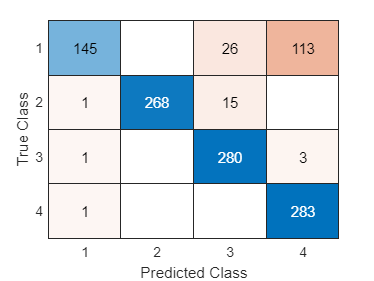

confusionchart(confusion_matrix)


%Συνολικα για την αναγνωριση των οργανων προτιμουμε ξεκαθαρα τους
%συντελεστες mfcc, καθως τα ποσοστα επιτυχιας ειναι πολυ καλυτερα σε
%συγκριση με την αναγνωριση με χρηση συντελεστων lpc.